# Chapter 1: The French-DeGroot model

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## 1.1 The French-DeGroot model of opinion formation

Describes a DT process of opinion formation in a group of $n$ agents, whose opinions are $x_1, \dots, x_n \text{ with } x_i\in\mathbb R$

System dynamics is described by the stochastic matrix $W = (w_{ij}) \in \mathbb R^{n \times n}$ where $w_{ij}>0, j=1, \dots, n$ defines the influence of agent $j$ on the opinion of agent $i$ at each time-step.

Hence the system equation is 

                                                             (M1.1)   $x(k+1) = Wx(k) = \sum_{j = 1}^nw_{ij}x_j(k) \forall i, \ k = 0, 1 , \dots$

The self-influence weight $w_{ii} \ge 0
$ indicates the agent's openness to the assimilation of other's opinions:

- $w_{ii} = 0
$ "open-minded" (completely relies on others' opinions)

- $w_{ii} = 1 \text{ and } w_{ij}=0 \forall j \neq i $ "stubborn" (anchored to its initial opinion $x_i (k) \equiv x_i(0) \text{ for } k = 0, 1 ,\dots
$

Agent's opinions can also be vectors $x^i = (x_{1i}, \dots,x_{mi})$, hence we get the opinion matrix $X = (x_{ii})\in \mathbb R ^ {n \times m}$ and we can rewrite the system dynamics as 

                                                                            (M1.2)    $X(k+1) = WX(k), \ k = 0,1, \dots$

Every column $x_i(k) = (x_{1i}(k),\dots x_{ni}(k))^T \in \mathbb R ^n \text{ of } X(k)$ evolves in accordance to M1. Hence M2 with a general stochastic matrix W is referred to as the French-DeGroot model.

## 1.2 Convergence and Conensus Criteria

The dynamics of M1.1 is "non-expansive" in the sense that 

                                                                            
$$\min_ix_i(0) \le \dots \le \min_ix_i(k) \le \min_ix_i(k+1) \\
\max_ix_i(0) \ge \dots \ge \max_ix_i(k) \ge \max_ix_i(k+1)$$


for any $k = 0, 1, \dots
$

Such system is Lyapunov stable but it such stability is not asymptotic since $W$ always has eigenvalue at $1$.

Such model is **convergent **if for any initial condition $x(0)$ the limits exists $x(\infty) = \lim_{k \rightarrow \infty}x(k) = \lim_{k \rightarrow \infty}W^kx(0)$. A convergent model reaches consensu if $x_1(\infty) = \dots = x_n(\infty)

$ for any initial coniditon.

We call the matrix $W$**regular **if the limit $W^\infty = \lim_{k\rightarrow \infty} W^k$ exists and **fully regular **if, additionally, the rows of $W^\infty$ are identical (**i.e. **$W^\infty = \mathbb 1_np_\infty^T$ for some $p_\infty \in \mathbb R^n$).

**Lemma 1.1 **The model M1.1 is convergent (ie $W$ regular) $\iff$ $\lambda = 1$ is the only eigenvalue of $W$ on the unit cricle $\left\{ \lambda \in \mathbb C :  | \lambda | = 1\right\}$. Such model reaches consensu (ie $W$ fully regular) $\iff$this eigenvalue is simple, i.e the corresponding eigenspace is spanned by the vector $\mathbb 1$.

**Lemma 1.2 **For an irreducibile stochastic matric $W$ the model M1.1 is convergent $\iff$ $W$ isp rimitive, ie $W^k$ is a positive matrix for large k. In this case consensus is also reached.

%qui metto un semplice esempio applicativo con matrici 2x2

**Lemma 1.3 **If the grap $\mathcal G = \mathcal G[W]$ is stroing, then the model M1.1 reaches a consensu $\iff$ $\mathcal G$ is aperiodic. Otherwise, the model is not convergent and opinions oscillate for almost all $x(0)$.

**Theorem 1.1 **The model M1.1 is convergent $\iff$ all closed strong components in $\mathcal G [W]$ are aperiodic. The model M1.1 reaches a consensus $\iff$ $\mathcal G[W]$ is quasi-strongly connected and the only closed strong component is aperiodic

**Corollary 1.1 **Let the agents' self-weights be positive $w_{ii}>0$ for all $i$. Then, the model M1.1 is convergent. It reaches a consensus $\iff$ $\mathcal G[W]$ is quasi-strongly connected (ie has a directed spanning tree).

## 1.3 French-DeGroot: Dual Markov chain and social power

Consider the French model with $n=3$ agents, corresponding to the following graph                                      

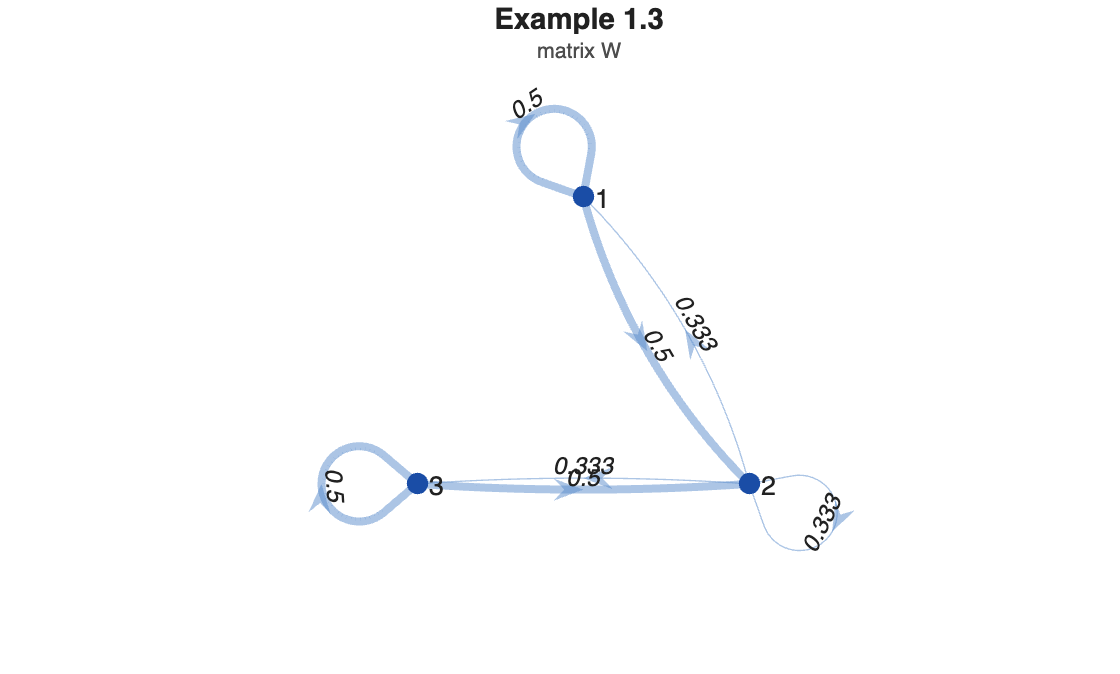

W = [1/2 1/2   0
     1/3 1/3 1/3
       0 1/2 1/2];
plot_graph(W, [], 'Title','Example 1.3', 'Subtitle','matrix W') 

`lot_graph(W, [], 'Title','Example 1.3', 'Subtitle','matrix W') `One can expect that the "central" node 2 corresponds to the most influential sgent in the group. Thisiis confirmed by a straightforward computation: solving the system of equation $p_\infty^T = p_\infty^TW$ and $p_\infty^T \mathbb 1 = 1$, one obtains the vector of social powers $p_\infty^T = (2/7, 3/7, 2/7)$

x0 = [3;-1;5]

x0 =      3
    -1
     5


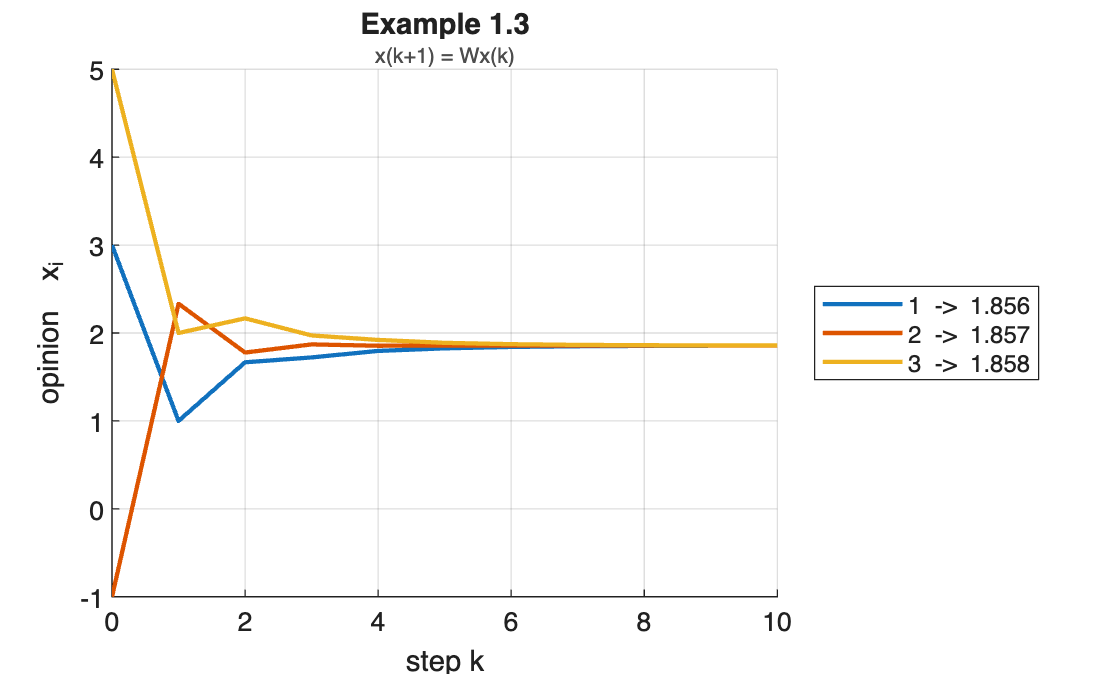

p  = social_power(W);          % p' = p'W,  p'1 = 1   ->  [2/7 3/7 2/7]
X  = sim_degroot(W, x0, 10);
plot_opinions(X, [], 'Title','Example 1.3', 'Subtitle','x(k+1) = Wx(k)')

p' * x0                        % the consensus value

ans = 1.8571

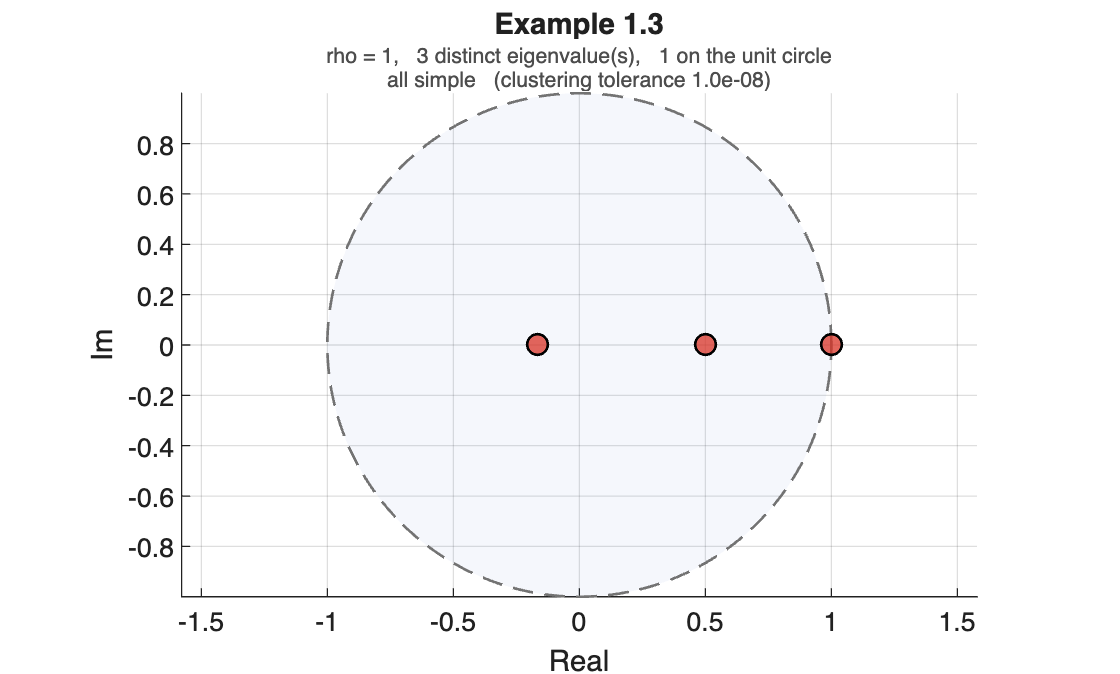

T = 3×5 table
     lambda        Re       Im    modulus    multiplicity
    ________    ________    __    _______    ____________

           1           1    0           1         1      
         0.5         0.5    0         0.5         1      
    -0.16667    -0.16667    0     0.16667         1      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','Example 1.3'); T

## 1.4 Stubborn agents in the French-DeGroot model

An agent is said to be **stubborn** if its opinion remains unchanged, independent of the other's opinions.

If the opinions obey the model  M1.1 then the agent $i$ is stubborn $x_i(k)\equiv x_i(0)$ $\iff$ $w_{ii}=1$. Such an agent corresponds to a source node in a graph $\mathcal G[W]$, ie a node having no incoming arcs but for the self-loop. **Theorem 1.1** implies that if $\mathcal G[W]$ has the only source, then the opinions reach a consensus (the source node is the opnly closed strong component of the graph).

If more than one stubborn agent exist (ie $\mathcal G[W]$ has several sources), then consensus among them is, obviously, impossible.  **Theorem 1.1** implies, however, that typically the opinions in such a group converge.

**Corollary 1.2 **Let the group have $s\ge1$ stubborn agents, influencing all other individuals (ie the set of source nodes is connected by walks to all other nodes of $\mathcal G[W]$. Then the model M1.1 is convergent.

Indeed, source nodes are the only closed strong components of $\mathcal G[W]$, which are obiously aperiodic.

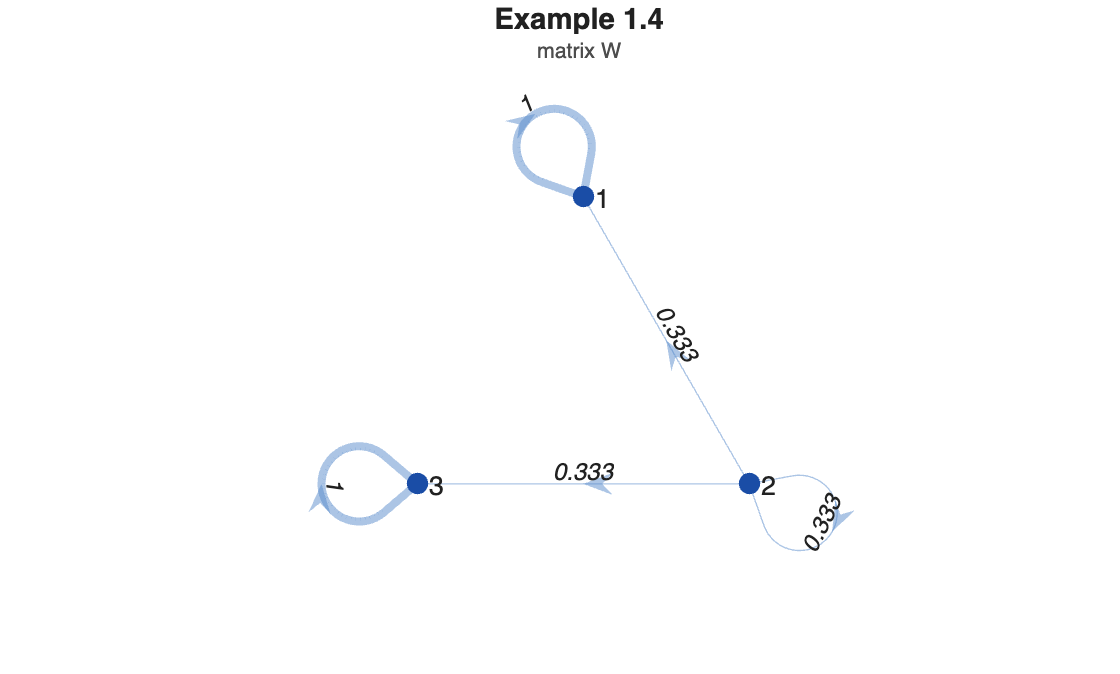

W = [1 0 0
     1/3 1/3 1/3
       0 0 1];
plot_graph(W, [], 'Title','Example 1.4', 'Subtitle','matrix W') 

x0 = [3;-1;5]

x0 =      3
    -1
     5


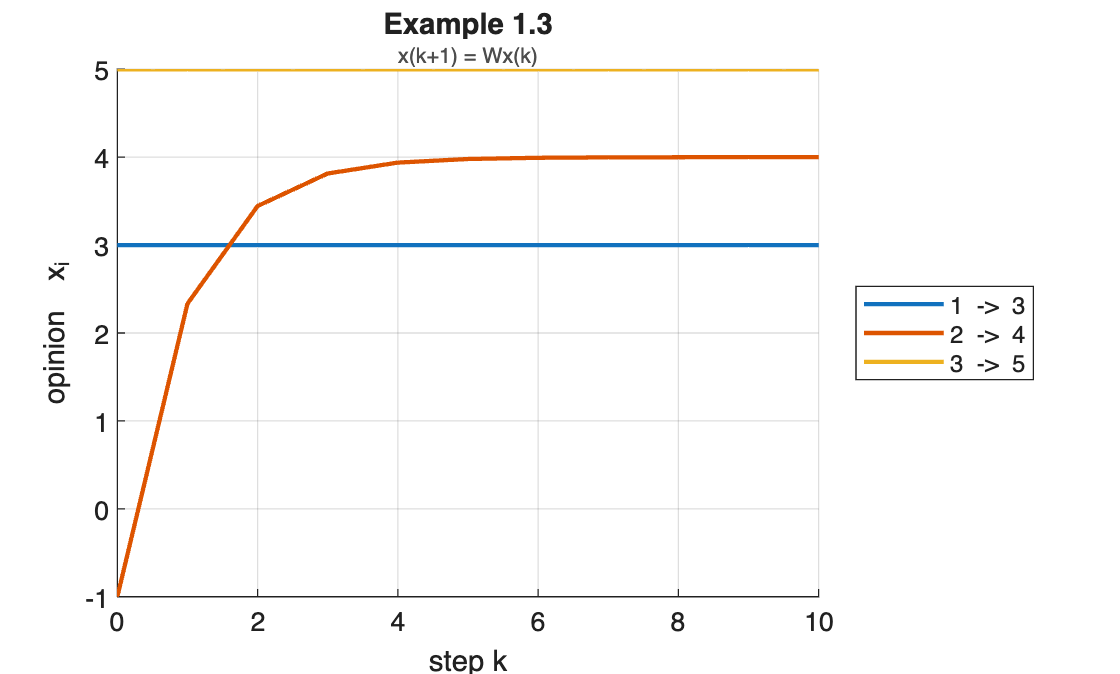

X  = sim_degroot(W, x0, 10);
plot_opinions(X, [], 'Title','Example 1.3', 'Subtitle','x(k+1) = Wx(k)')

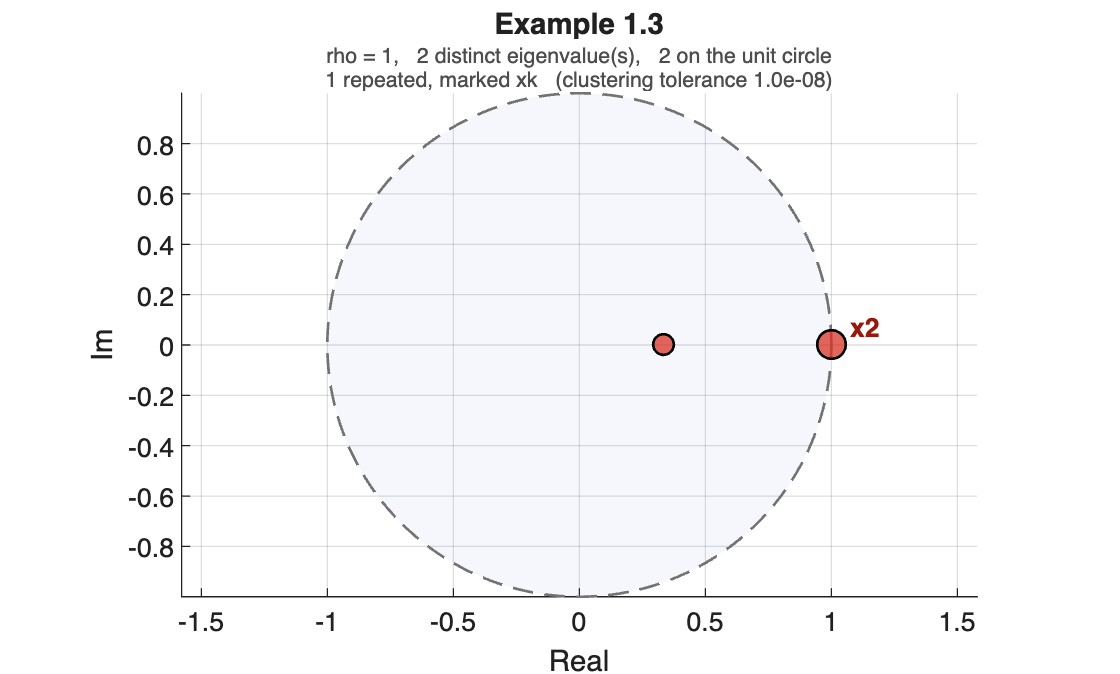

T = 2×5 table
    lambda       Re       Im    modulus    multiplicity
    _______    _______    __    _______    ____________

          1          1    0           1         2      
    0.33333    0.33333    0     0.33333         1      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','Example 1.3'); T

## 1.5 Examples

The same French-DeGroot model is applied to six topologies on N = 6 nodes. The number of agents, the initial condition and the horizon are identical in every example, so any difference in the outcome is attributable to the topology alone.

Each example follows the same six steps: topology, matrix and structural information, graph, state evolution, spectrum, short observation.

N  = 6;
x0 = [3; -1; 5; 0; 2; -2];      % the same initial condition in every example
K  = 30;                        % the same horizon

fprintf('N = %d, mean x0 = %.4f\n', N, mean(x0));

N = 6, mean x0 = 1.1667


## 1.5.1 Bidirectional cycle

Every edge of the ring made two-way.

A = ring_graph(N) + ring_graph(N).';      % every edge two-way
W = row_stochastic(A)

W =          0    0.5000         0         0         0    0.5000
    0.5000         0    0.5000         0         0         0
         0    0.5000         0    0.5000         0         0
         0         0    0.5000         0    0.5000         0
         0         0         0    0.5000         0    0.5000
    0.5000         0         0         0    0.5000         0


s = matrix_report(W, 'W');

W   (6 agents)
  out-degrees (row sums): [1 1 1 1 1 1]   row-stochastic : yes
  in-degrees  (col sums): [1 1 1 1 1 1]   weight-balanced: yes
  strong components  : 1   closed: 1   periods: 2
  rooted: yes   convergent: no    consensus: no


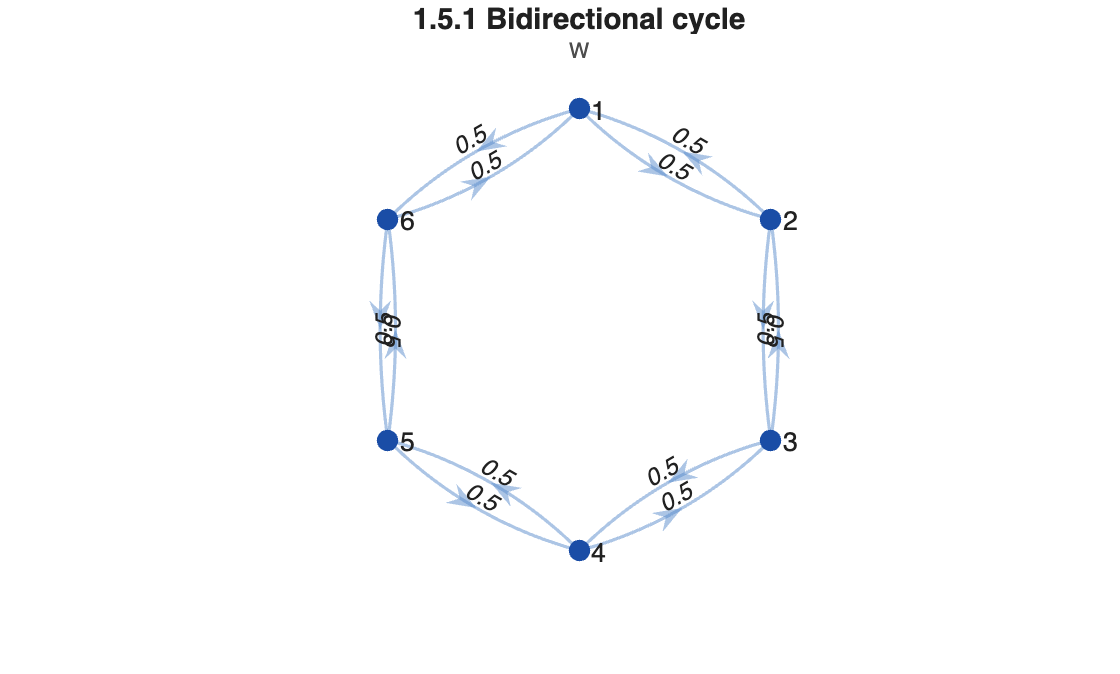

figure; plot_graph(W, [], 'Title','1.5.1 Bidirectional cycle', 'Subtitle','W')

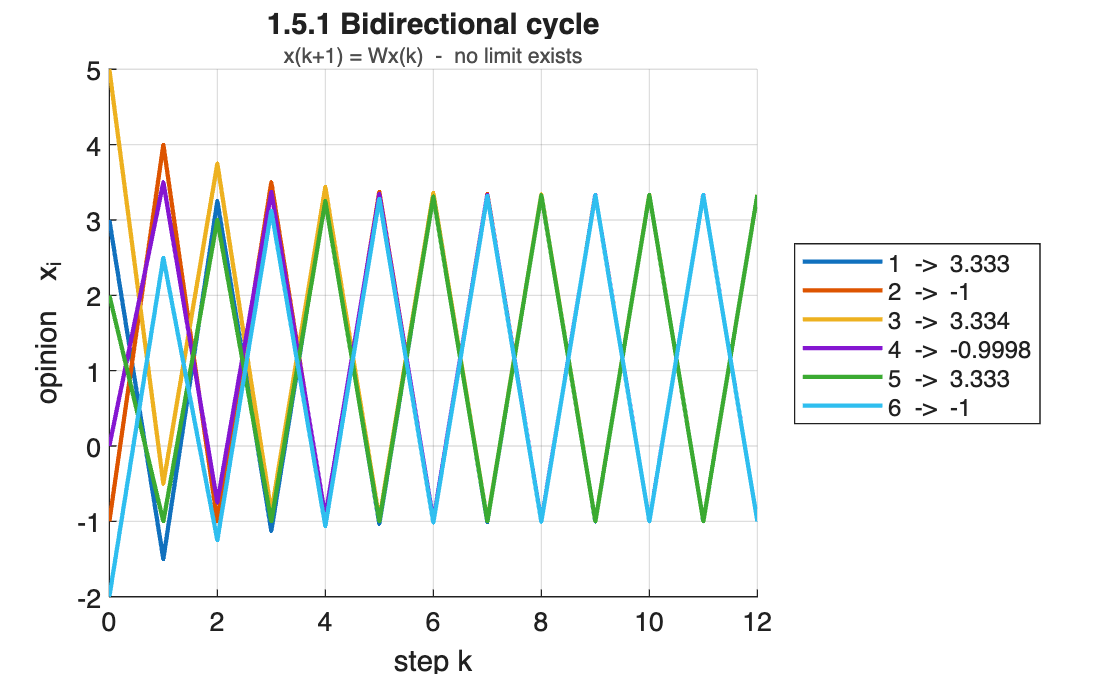

X = sim_degroot(W, x0, 12);
figure; plot_opinions(X, [], 'Title','1.5.1 Bidirectional cycle', ...
                             'Subtitle','x(k+1) = Wx(k)  -  no limit exists')

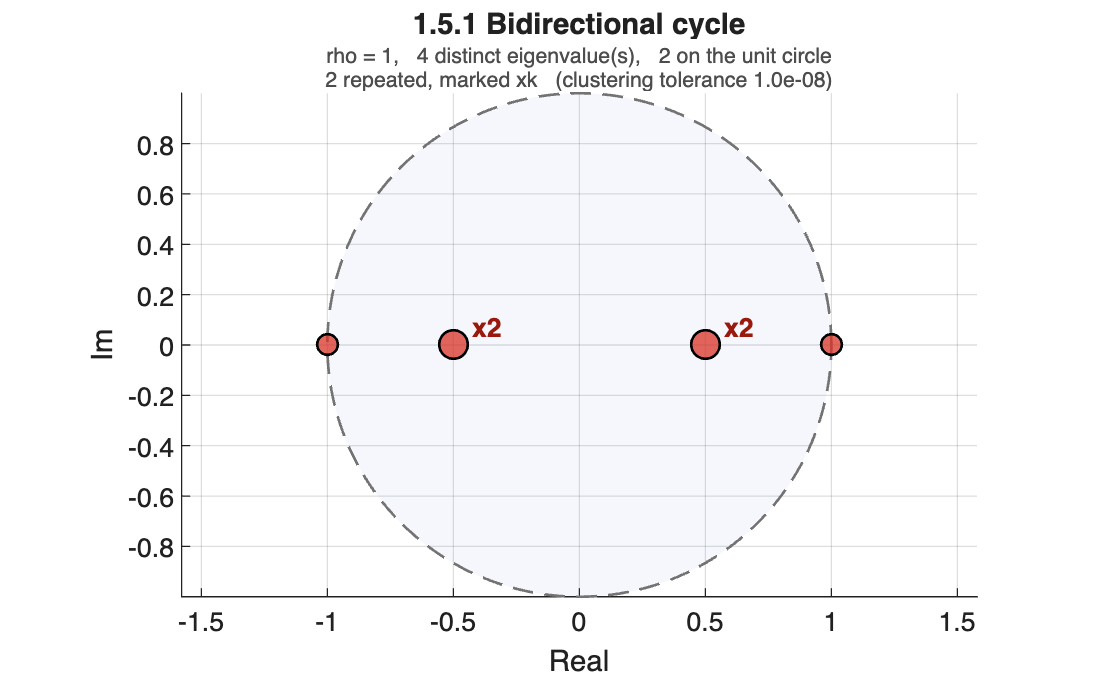

T = 4×5 table
    lambda     Re     Im    modulus    multiplicity
    ______    ____    __    _______    ____________

        1        1    0         1           1      
       -1       -1    0         1           1      
      0.5      0.5    0       0.5           2      
     -0.5     -0.5    0       0.5           2      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','1.5.1 Bidirectional cycle'); T


fprintf('period:  N = 6 -> %d,   N = 5 -> %d\n', graph_period(A), ...
        graph_period(ring_graph(5) + ring_graph(5).'));

period:  N = 6 -> 2,   N = 5 -> 1


Every cycle has even length on an even ring, so the period is 2 and the model oscillates. For odd N the period is 1.

## 1.5.2 Directed cycle

Each agent listens only to its predecessor. The graph is strongly connected, so W is irreducible, but its only cycle has length 6: the graph is periodic with period 6.

A = common_topology('cycle');
W = row_stochastic(A)

W =      0     0     0     0     0     1
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0


s = matrix_report(W, 'W');

W   (6 agents)
  out-degrees (row sums): [1 1 1 1 1 1]   row-stochastic : yes
  in-degrees  (col sums): [1 1 1 1 1 1]   weight-balanced: yes
  strong components  : 1   closed: 1   periods: 6
  rooted: yes   convergent: no    consensus: no


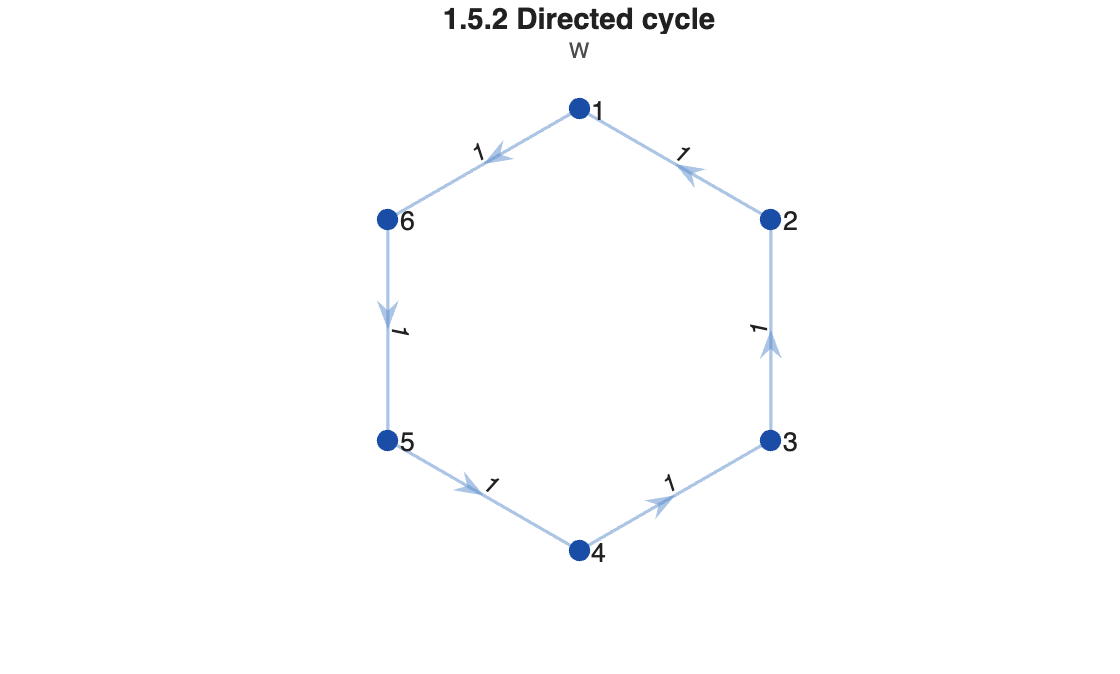

figure; plot_graph(W, [], 'Title','1.5.2 Directed cycle', 'Subtitle','W')

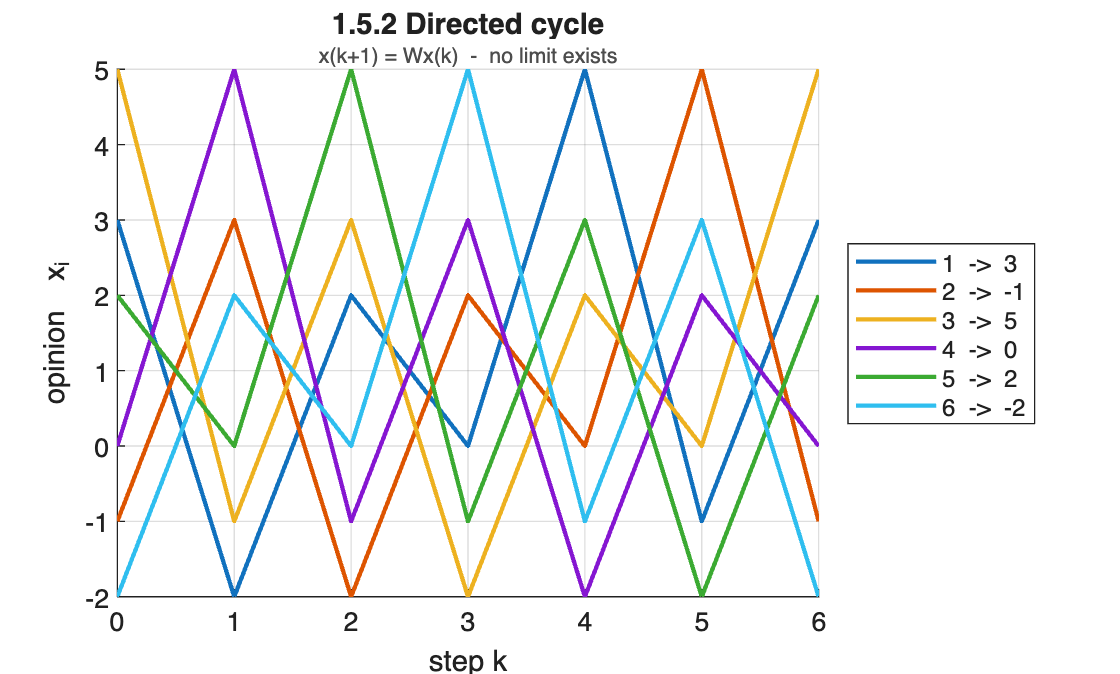

X = sim_degroot(W, x0, 6);
figure; plot_opinions(X, [], 'Title','1.5.2 Directed cycle', ...
                             'Subtitle','x(k+1) = Wx(k)  -  no limit exists')

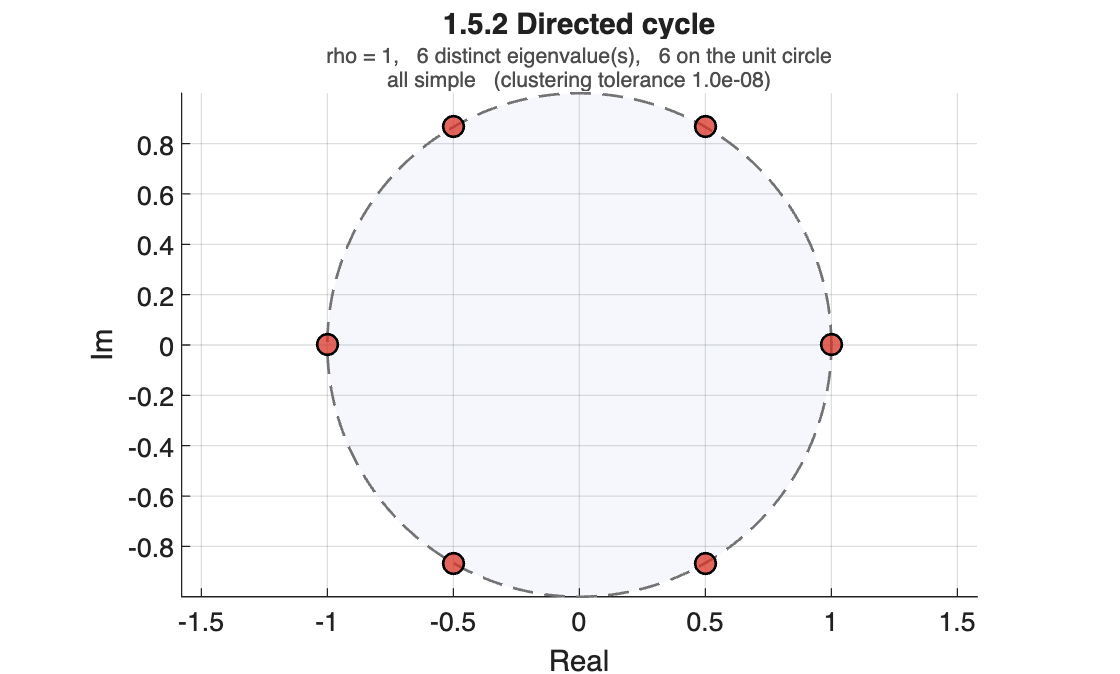

T = 6×5 table
       lambda         Re        Im       modulus    multiplicity
    _____________    ____    ________    _______    ____________

       1+0i             1           0       1            1      
    -0.5+0.86603i    -0.5     0.86603       1            1      
    -0.5-0.86603i    -0.5    -0.86603       1            1      
      -1+0i            -1           0       1            1      
     0.5+0.86603i     0.5     0.86603       1            1      
     0.5-0.86603i     0.5    -0.86603       1            1      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','1.5.2 Directed cycle'); T

W is a permutation matrix: the opinions are passed round the ring unchanged and repeat with period 6. All six eigenvalues are simple and lie on the unit circle, so the eigenvalue 1 is not strictly dominant and the model is not convergent.

## 1.5.3 Directed cycle with one self-loop

The only change is a self-loop on agent 1. It creates a cycle of length 1, so the period becomes gcd(1,6) = 1 and W is primitive.

A = common_topology('cycle-self');
W = row_stochastic(A)

W =     0.5000         0         0         0         0    0.5000
    1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0


s = matrix_report(W, 'W');

W   (6 agents)
  out-degrees (row sums): [1 1 1 1 1 1]   row-stochastic : yes
  in-degrees  (col sums): [1.5 1 1 1 1 0.5]   weight-balanced: no
  strong components  : 1   closed: 1   periods: 1
  rooted: yes   convergent: yes   consensus: yes


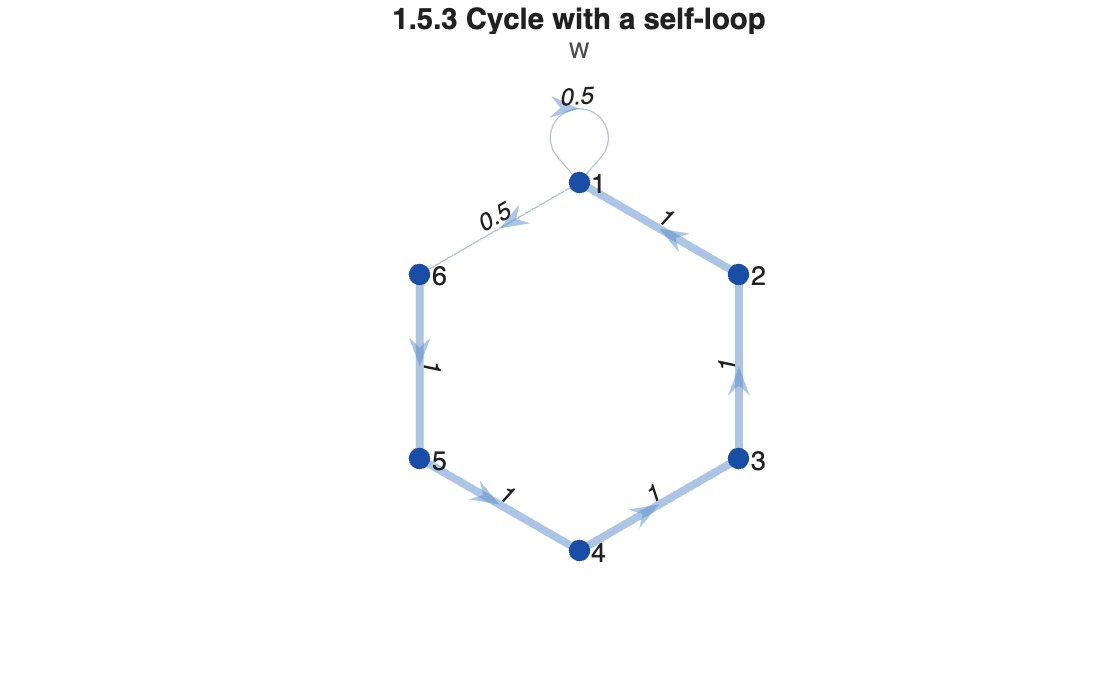

figure; plot_graph(W, [], 'Title','1.5.3 Cycle with a self-loop', 'Subtitle','W')

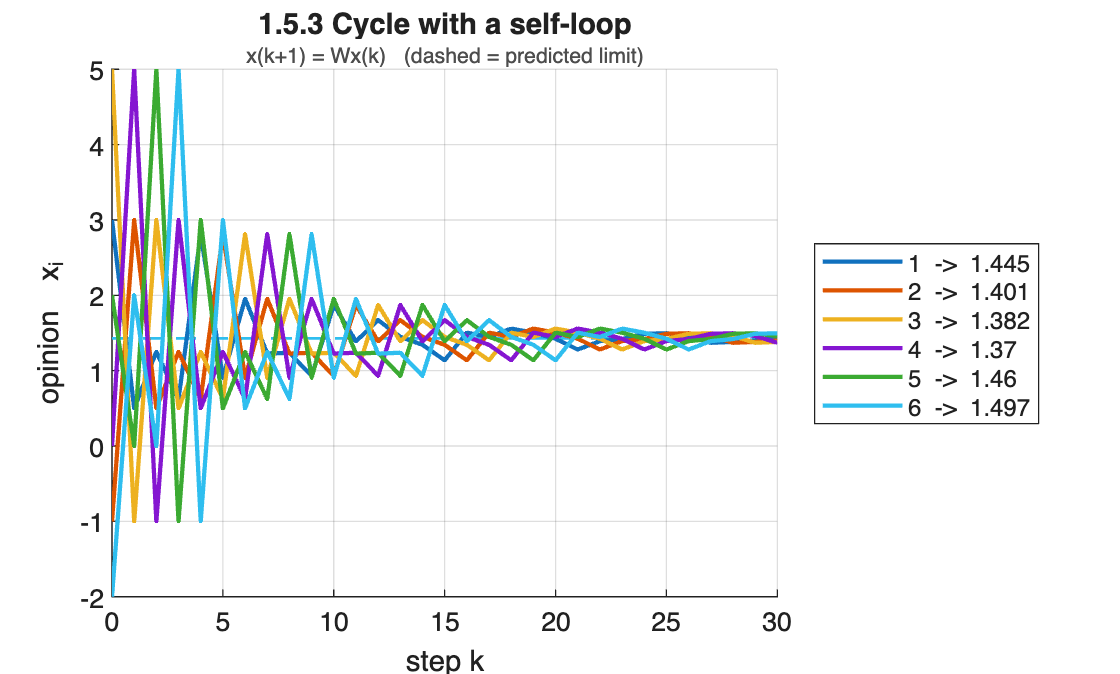

p    = social_power(W);
xinf = limit_matrix(W) * x0;
X    = sim_degroot(W, x0, K);
figure; plot_opinions(X, [], 'Limit', xinf, 'Title','1.5.3 Cycle with a self-loop', ...
                             'Subtitle','x(k+1) = Wx(k)   (dashed = predicted limit)')

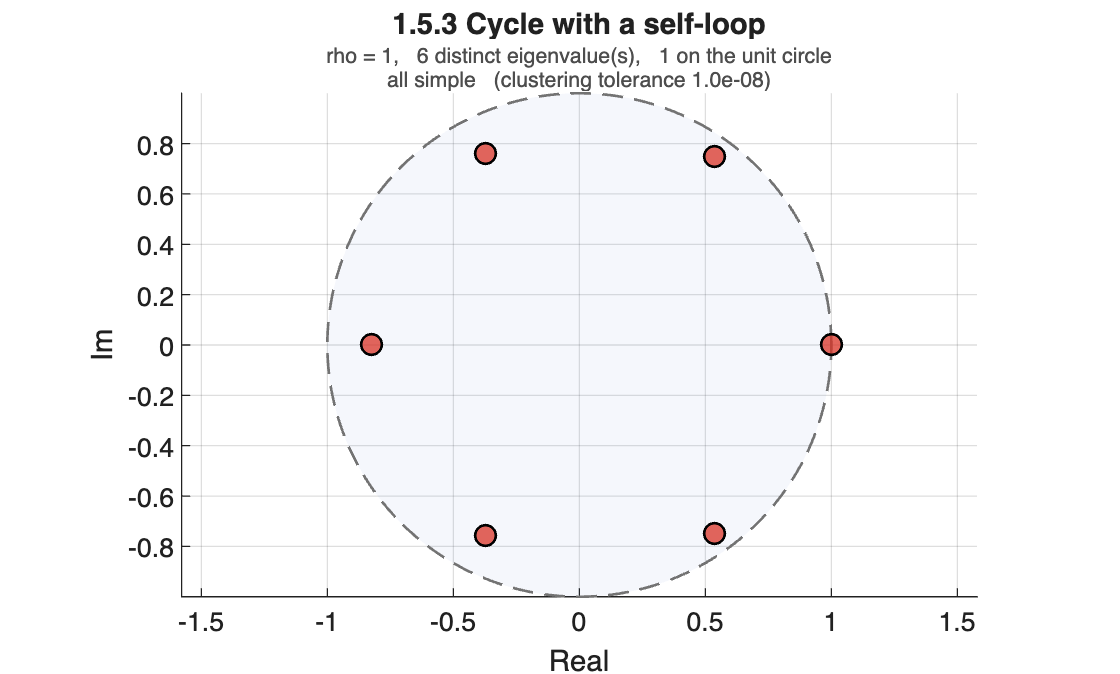

T = 6×5 table
         lambda            Re         Im       modulus    multiplicity
    ________________    ________    _______    _______    ____________

           1+0i                1          0          1         1      
     0.53484+0.7507i     0.53484     0.7507    0.92174         1      
     0.53484-0.7507i     0.53484    -0.7507    0.92174         1      
    -0.37327+0.7587i    -0.37327     0.7587    0.84555         1      
    -0.37327-0.7587i    -0.37327    -0.7587    0.84555         1      
    -0.82314+0i         -0.82314          0    0.82314         1      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','1.5.3 Cycle with a self-loop'); T

fprintf('social power p'' = %s\n', mat2str(round(p.',4)));

social power p' = [0.2857 0.1429 0.1429 0.1429 0.1429 0.1429]


fprintf('consensus value = %.4f\n', p.' * x0);

consensus value = 1.4286


One edge turns oscillation into consensus. The eigenvalue 1 is now simple and strictly dominant, and the group settles at px(0). Note that the self-loop also makes agent 1 the most influential agent, so the limit is not the plain average.

### Adding self-loops one at a time

1.5.2 and 1.5.3 are the two ends of one experiment: the same directed cycle with m = 0 and with m = 1 self-loops. Letting m run from 0 to 6 turns that pair into a progression, and the effect of a self-loop becomes a movement of the spectrum rather than a single before-and-after comparison.

A self-loop on agent i is one extra unit on the diagonal of A, so the whole family is generated by one line.

% A self-loop on agent i is one extra unit on the diagonal of A.
selfloops = @(m) ring_graph(N) + diag([ones(m,1); zeros(N-m,1)]);

M = arrayfun(@(m) row_stochastic(selfloops(m)), 0:N, 'UniformOutput', false);

for m = 0:N
    fprintf('m = %d   diag(W) = %s\n', m, mat2str(diag(M{m+1}).', 4));
end

m = 0   diag(W) = [0 0 0 0 0 0]
m = 1   diag(W) = [0.5 0 0 0 0 0]
m = 2   diag(W) = [0.5 0.5 0 0 0 0]
m = 3   diag(W) = [0.5 0.5 0.5 0 0 0]
m = 4   diag(W) = [0.5 0.5 0.5 0.5 0 0]
m = 5   diag(W) = [0.5 0.5 0.5 0.5 0.5 0]
m = 6   diag(W) = [0.5 0.5 0.5 0.5 0.5 0.5]


All seven spectra on one plot, the colour running from the plain cycle (m = 0) to the fully lazy cycle (m = 6).

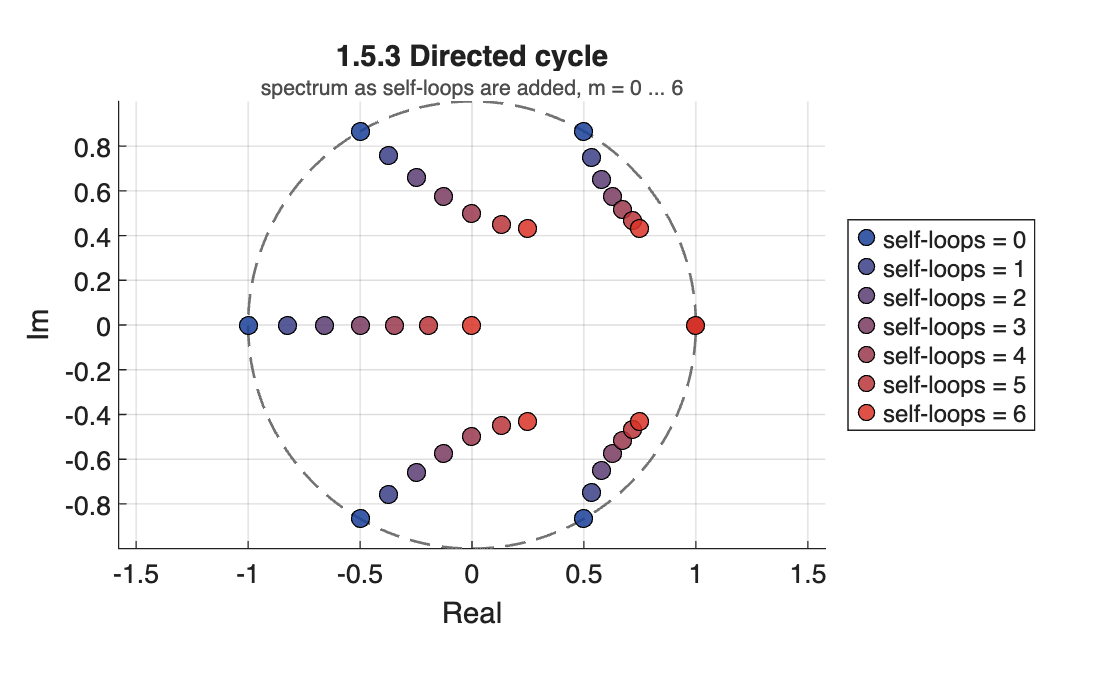

figure;
T = plot_spectrum_family(M, 0:N, 'discrete', 'Label','self-loops', ...
        'Title','1.5.3 Directed cycle', ...
        'Subtitle','spectrum as self-loops are added, m = 0 ... 6');

The same seven spectra one at a time, so that each case can also be read on its own. Each panel is an ordinary plot_eigenvalues call, so the multiplicity rule of the single-matrix plot applies unchanged to every case.

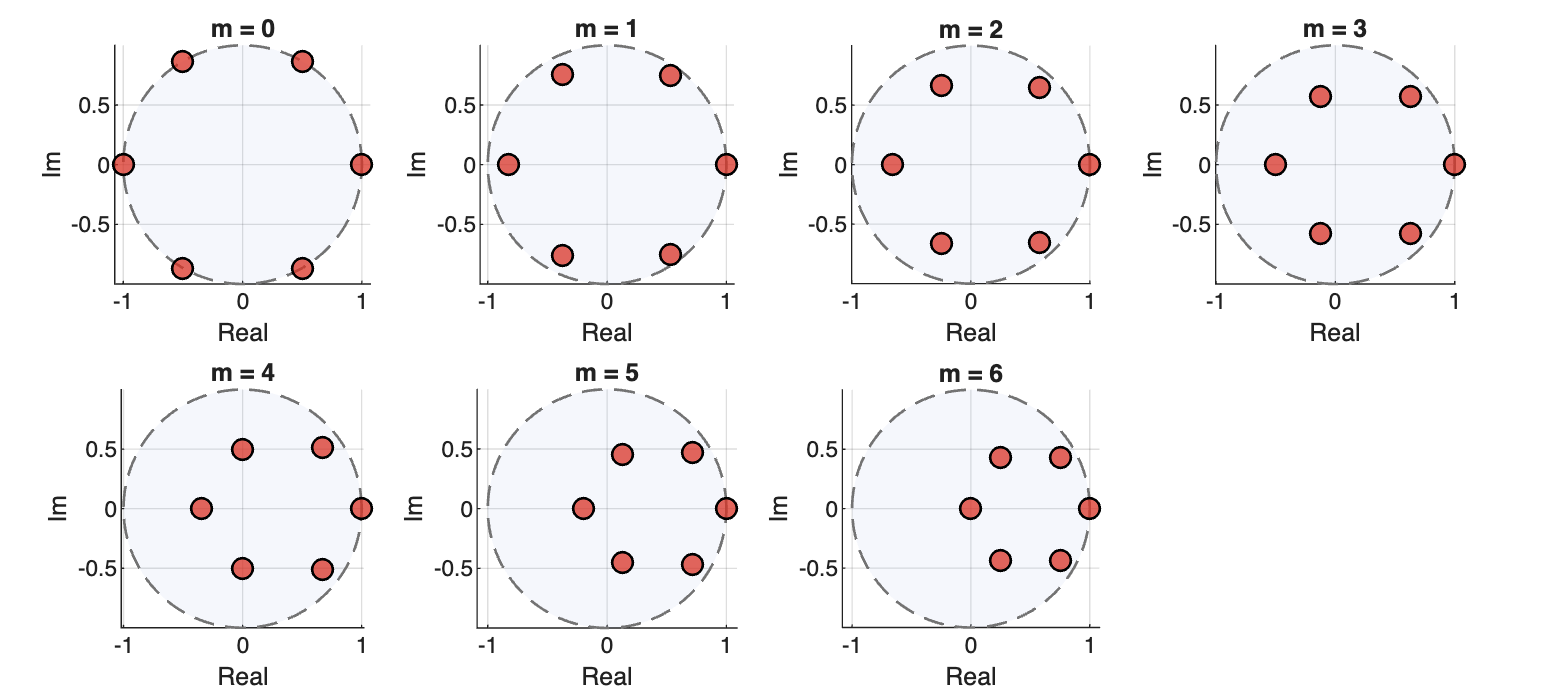

figure('Position',[0 0 1250 560]);
tiledlayout(2, 4, 'TileSpacing','compact', 'Padding','compact');
for m = 0:N
    nexttile;
    plot_eigenvalues(M{m+1}, 'discrete', 'Title', sprintf('m = %d', m), 'Subtitle','');
end

The picture has an exact algebraic counterpart. In a directed cycle where agent i has self-weight a_i and listens to its predecessor with weight b_i, the characteristic polynomial is prod(lambda - a_i) - prod(b_i). With m self-loops the self-looped rows are (1/2, 1/2) and the rest are (0, 1), so

        det(lambda*I - W)  =  (lambda - 1/2)^m * lambda^(N-m)  -  (1/2)^m .

Two consequences follow at once. Both products are symmetric in the rows, so the spectrum depends only on HOW MANY self-loops there are and not on WHICH agents carry them. And lambda = 1 is a root for every m, as it must be for a row-stochastic matrix. The cell below checks both claims numerically.

residual = zeros(N+1, 1);
for m = 0:N
    ev = eig(M{m+1});
    residual(m+1) = max(abs((ev - 1/2).^m .* ev.^(N-m) - (1/2)^m));
end
fprintf('largest residual of the analytic characteristic polynomial: %.2e\n', max(residual));

largest residual of the analytic characteristic polynomial: 4.51e-15



% the same number of self-loops, three different placements
placements = {[1 2], [1 3], [1 4]};
for k = 1:numel(placements)
    A = ring_graph(N);
    A(sub2ind([N N], placements{k}, placements{k})) = 1;
    fprintf('self-loops at %-8s |lambda| = %s\n', mat2str(placements{k}), ...
        mat2str(round(sort(abs(eig(row_stochastic(A))), 'descend').', 4)));
end

self-loops at [1 2]    |lambda| = [1 0.8722 0.8722 0.7071 0.7071 0.6573]
self-loops at [1 3]    |lambda| = [1 0.8722 0.8722 0.7071 0.7071 0.6573]
self-loops at [1 4]    |lambda| = [1 0.8722 0.8722 0.7071 0.7071 0.6573]


Adding self-loops pulls the spectrum off the unit circle. At m = 0 all six eigenvalues lie on it, evenly spaced, and the model only rotates the opinions. The first self-loop is the decisive one: it leaves lambda = 1 exactly where it is and drags the other five strictly inside, and that single fact is the whole of the difference between 1.5.2 and 1.5.3. Each further self-loop moves the spectrum further in, never off lambda = 1, and at m = 6 the six eigenvalues sit on the circle of radius 1/2 centred at 1/2: with a self-loop everywhere W = (I + P)/2, so the spectrum is the image of the six roots of unity under lambda -> (1 + lambda)/2. The seven markers at lambda = 1 coincide exactly, which is why only one is visible there.

The three placements confirm the algebra: identical moduli, so the spectrum counts self-loops and ignores where they sit. This is a statement about the spectrum only. The social power vector, and with it the consensus value, does depend on which agents carry the self-loops, so comparing the consensus behaviour across these cases is a separate question.

### The same comparison, in terms of consensus

The spectrum decides how fast the group agrees. It says nothing about what it agrees on. In this family the two questions separate exactly, so they are worth asking one at a time.

How fast. The disagreement spread max_i x_i - min_i x_i, one curve per m, beside the second-largest modulus that sets its slope. One curve per case instead of six trajectories keeps seven cases on one pair of axes.

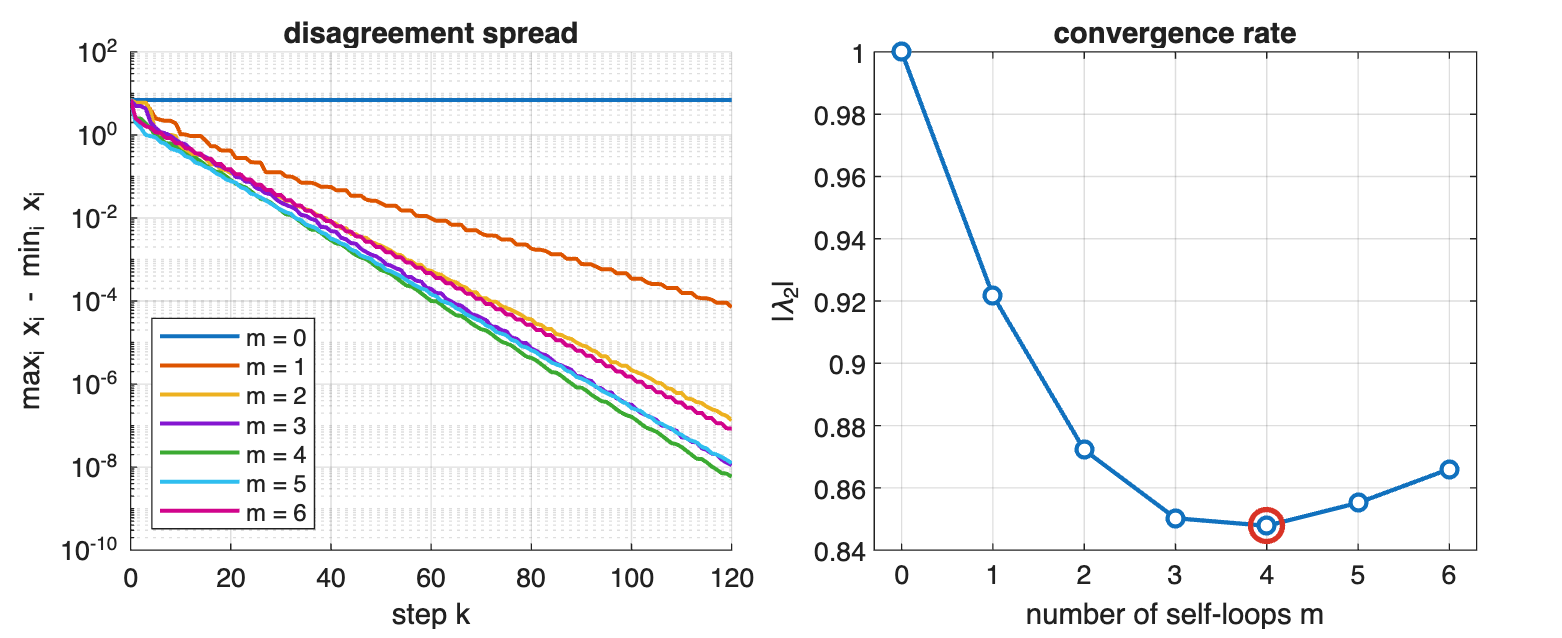

K2 = 120;
lambda2 = zeros(1, N+1);

figure('Position',[0 0 1150 470]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');

nexttile; hold on
for m = 0:N
    X = sim_degroot(M{m+1}, x0, K2);
    plot(0:K2, max(X,[],1) - min(X,[],1), 'LineWidth', 1.5, ...
         'DisplayName', sprintf('m = %d', m));
    e = sort(abs(eig(M{m+1})), 'descend');
    lambda2(m+1) = e(2);
end
set(gca, 'YScale', 'log'); grid on; legend('Location','southwest');
xlabel('step k'); ylabel('max_i x_i - min_i x_i');
title('disagreement spread', 'FontWeight','bold');

nexttile
plot(0:N, lambda2, 'o-', 'LineWidth', 1.6, 'MarkerFaceColor', 'w'); grid on; hold on
[fastest, at] = min(lambda2);
plot(at-1, fastest, 'o', 'MarkerSize', 12, 'LineWidth', 2, 'Color', [0.85 0.20 0.15]);
xlabel('number of self-loops m'); ylabel('|\lambda_2|');
title('convergence rate', 'FontWeight','bold'); xlim([-0.3 N+0.3]);


fprintf('fastest at m = %d of %d, |lambda2| = %.4f\n', at-1, N, fastest);

fastest at m = 4 of 6, |lambda2| = 0.8478


What it agrees on. The consensus value is px(0), so the social power vector is the compact summary of the limit: six numbers per case, whatever the trajectories look like.

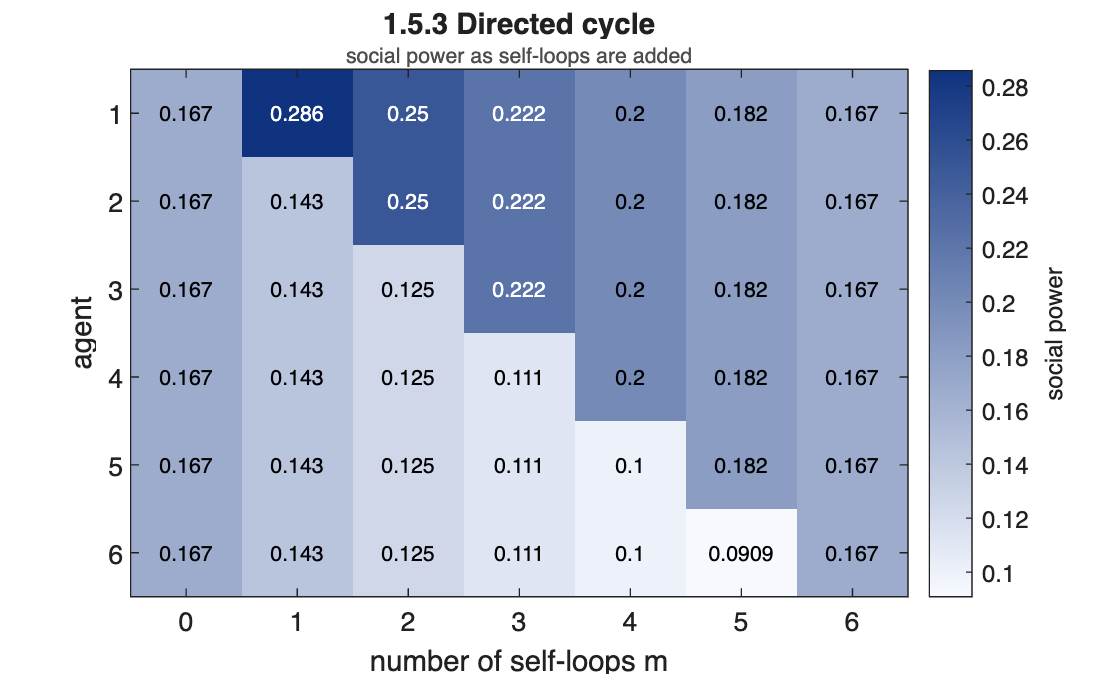

Pm = cell2mat(arrayfun(@(m) social_power(M{m+1}), 0:N, 'UniformOutput', false));

figure;
plot_sweep(Pm, 0:N, [], 'Label','number of self-loops m', 'Name','social power', ...
    'Title','1.5.3 Directed cycle', ...
    'Subtitle','social power as self-loops are added')


fprintf('\n  m   consensus value p''x(0)\n');


  m   consensus value p'x(0)


for m = 0:N
    fprintf('  %d   %+.4f\n', m, Pm(:,m+1).' * x0);
end

  0   +1.1667
  1   +1.4286
  2   +1.1250
  3   +1.5556
  4   +1.4000
  5   +1.4545
  6   +1.1667


fprintf('  mean(x0) = %+.4f\n', mean(x0));

  mean(x0) = +1.1667


The heatmap has an exact closed form behind it. Writing s_i = 1 when agent i carries a self-loop and 0 otherwise, pW = p is solved by

        p_i  =  (1 + s_i) / (N + m) ,

so a self-looped agent carries exactly twice the social power of a plain one, whatever N and m are. That is the staircase in the picture. It also explains the two ends: at m = 0 and at m = 6 nobody is singled out and the power is uniform, 1/6 each, while every case in between is unequal in the ratio 2:1. Only at m = 6 does that uniform power actually produce a limit, and there the group converges to the plain average of the initial opinions.

Placement. The rate ignores it; the limit does not. Three different placements of the same three self-loops:

sets = {[1 2 3], [1 3 5], [2 4 6]};
Pp = zeros(N, numel(sets));

fprintf('\n  placement    |lambda2|   consensus value\n');


  placement    |lambda2|   consensus value


for k = 1:numel(sets)
    A = ring_graph(N);
    A(sub2ind([N N], sets{k}, sets{k})) = 1;
    Wk = row_stochastic(A);
    Pp(:,k) = social_power(Wk);
    e = sort(abs(eig(Wk)), 'descend');
    fprintf('  %-10s   %.4f      %+.4f\n', mat2str(sets{k}), e(2), Pp(:,k).' * x0);
end

  [1 2 3]      0.8502      +1.5556
  [1 3 5]      0.8502      +1.8889
  [2 4 6]      0.8502      +0.4444


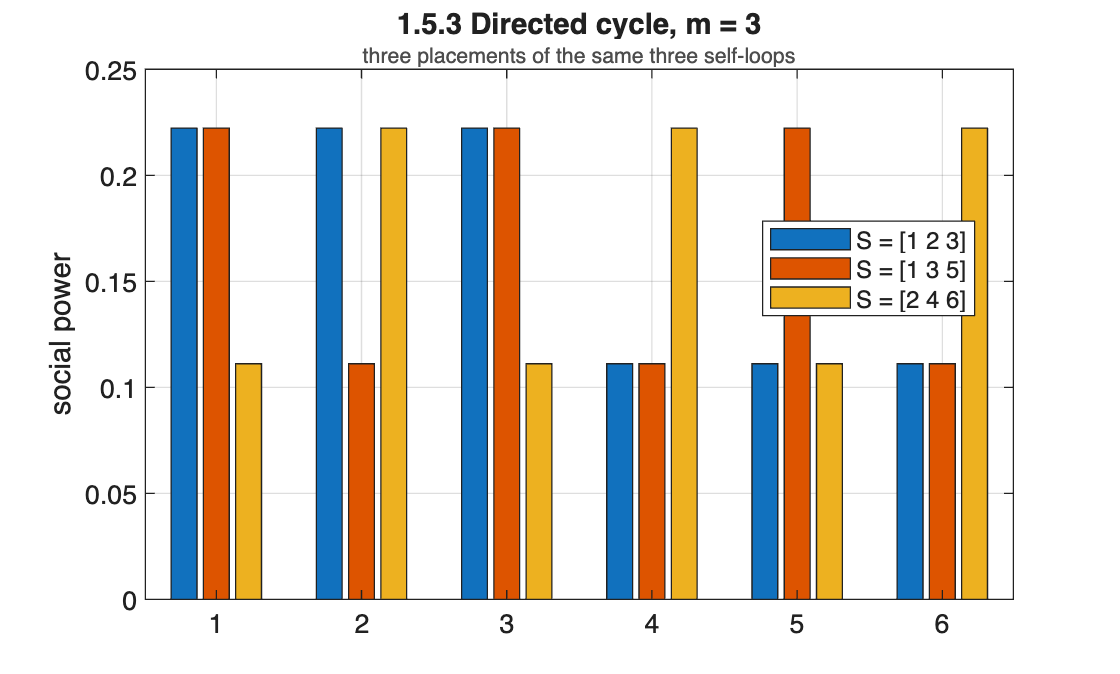


figure;
plot_bars(Pp, [], 'YLabel','social power', ...
    'Series', cellfun(@(t) sprintf('S = %s', mat2str(t)), sets, 'UniformOutput', false), ...
    'Title','1.5.3 Directed cycle, m = 3', ...
    'Subtitle','three placements of the same three self-loops')

Two results, and they pull apart cleanly. The convergence rate is a function of the NUMBER of self-loops alone, and it is not monotone: the first self-loop buys by far the most, the gain shrinks, and past roughly half the agents adding more actually slows the group down again. The consensus value is a function of WHICH agents carry them, and the three placements above spread it over a range wider than the gap between any two numbers of self-loops. So "add more self-loops" is a statement about speed, and "add them here rather than there" is a statement about the outcome; neither answers the other question.

## 1.5.4 Directed line

A chain in which agent 1 listens only to itself and every other agent listens to its predecessor. The graph is not strongly connected, so W is reducible, but agent 1 is a globally reachable node and it is the only closed strong component.

A = common_topology('line');
W = row_stochastic(A)

W =      1     0     0     0     0     0
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0


s = matrix_report(W, 'W');

W   (6 agents)
  out-degrees (row sums): [1 1 1 1 1 1]   row-stochastic : yes
  in-degrees  (col sums): [2 1 1 1 1 0]   weight-balanced: no
  strong components  : 6   closed: 1   periods: [0 0 0 0 0 1]
  rooted: yes   convergent: yes   consensus: yes


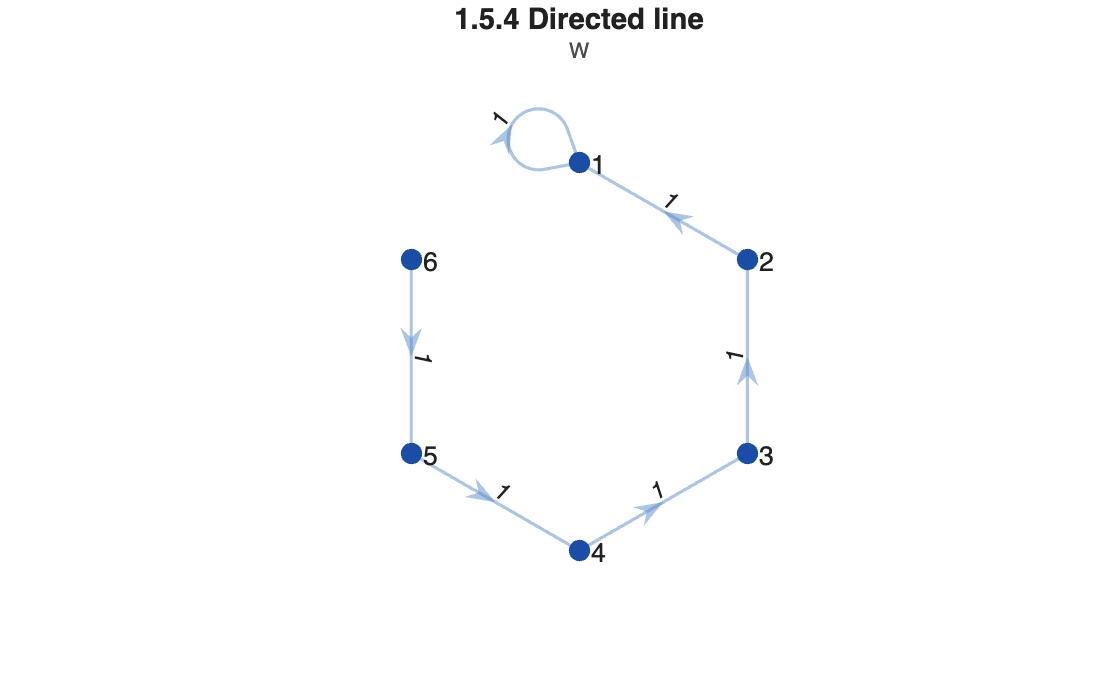

figure; plot_graph(W, [], 'Title','1.5.4 Directed line', 'Subtitle','W')

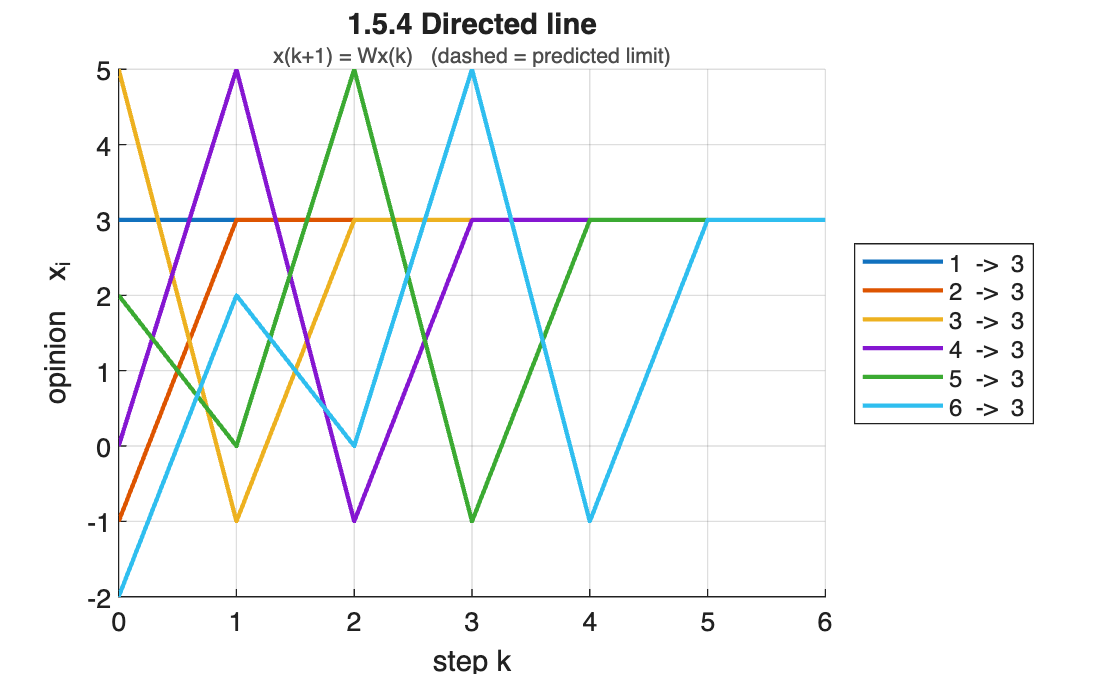

xinf = limit_matrix(W) * x0;
X    = sim_degroot(W, x0, 6);
figure; plot_opinions(X, [], 'Limit', xinf, 'Title','1.5.4 Directed line', ...
                             'Subtitle','x(k+1) = Wx(k)   (dashed = predicted limit)')

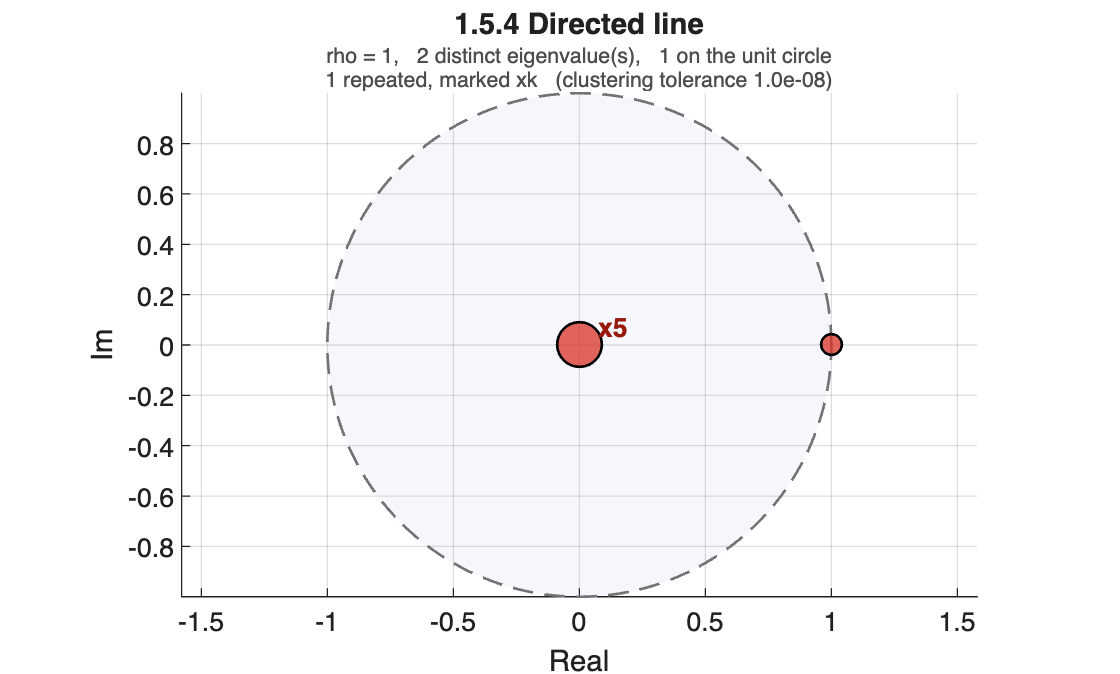

T = 2×5 table
    lambda    Re    Im    modulus    multiplicity
    ______    __    __    _______    ____________

      1       1     0        1            1      
      0       0     0        0            5      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','1.5.4 Directed line'); T

fprintf('social power p'' = %s\n', mat2str(round(social_power(W).',4)));

social power p' = [1 0 0 0 0 0]


fprintf('consensus value = %.4f   (= x1(0) = %.4f)\n', xinf(1), x0(1));

consensus value = 3.0000   (= x1(0) = 3.0000)


Consensus is reached at the initial opinion of the single source: every other initial opinion is forgotten, and the social power vector is e1. The spectrum shows the eigenvalue 0 with multiplicity 5, which is why the limit is attained exactly after 5 steps rather than asymptotically.

## 1.5.5 Bidirectional star

A hub connected to five leaves in both directions. The graph is strongly connected, but every closed walk alternates between hub and leaves, so all cycles have even length and the period is 2.

A = common_topology('star');
W = row_stochastic(A)

W =          0    0.2000    0.2000    0.2000    0.2000    0.2000
    1.0000         0         0         0         0         0
    1.0000         0         0         0         0         0
    1.0000         0         0         0         0         0
    1.0000         0         0         0         0         0
    1.0000         0         0         0         0         0


s = matrix_report(W, 'W');

W   (6 agents)
  out-degrees (row sums): [1 1 1 1 1 1]   row-stochastic : yes
  in-degrees  (col sums): [5 0.2 0.2 0.2 0.2 0.2]   weight-balanced: no
  strong components  : 1   closed: 1   periods: 2
  rooted: yes   convergent: no    consensus: no


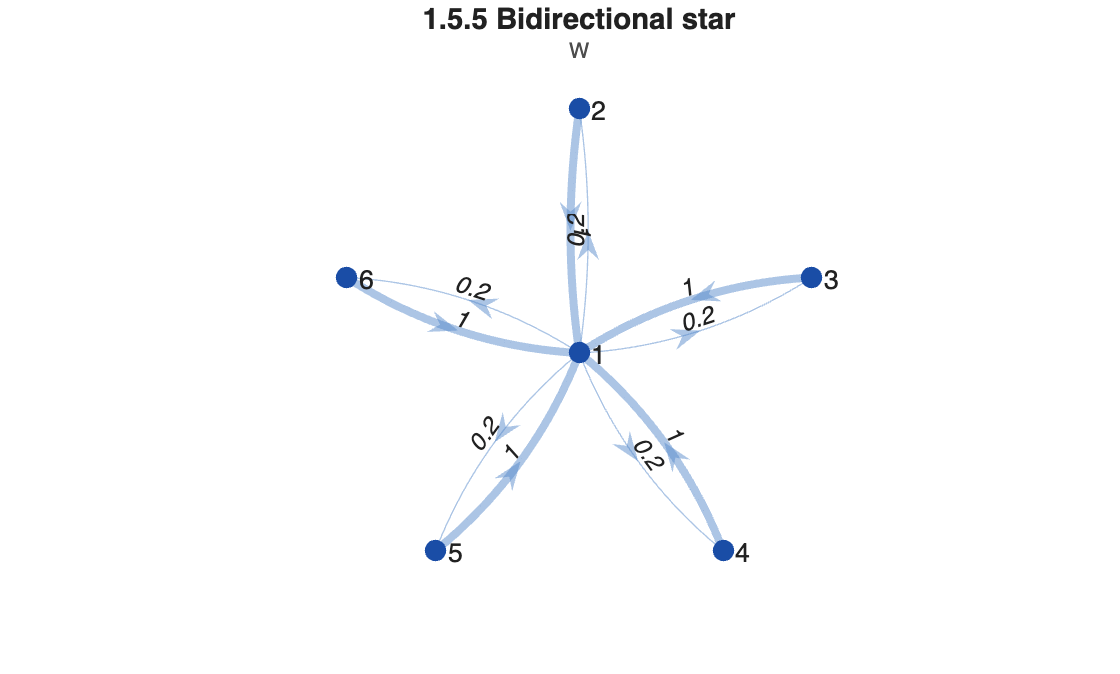

figure; plot_graph(W, [], 'Layout','star', ...
                  'Title','1.5.5 Bidirectional star', 'Subtitle','W')

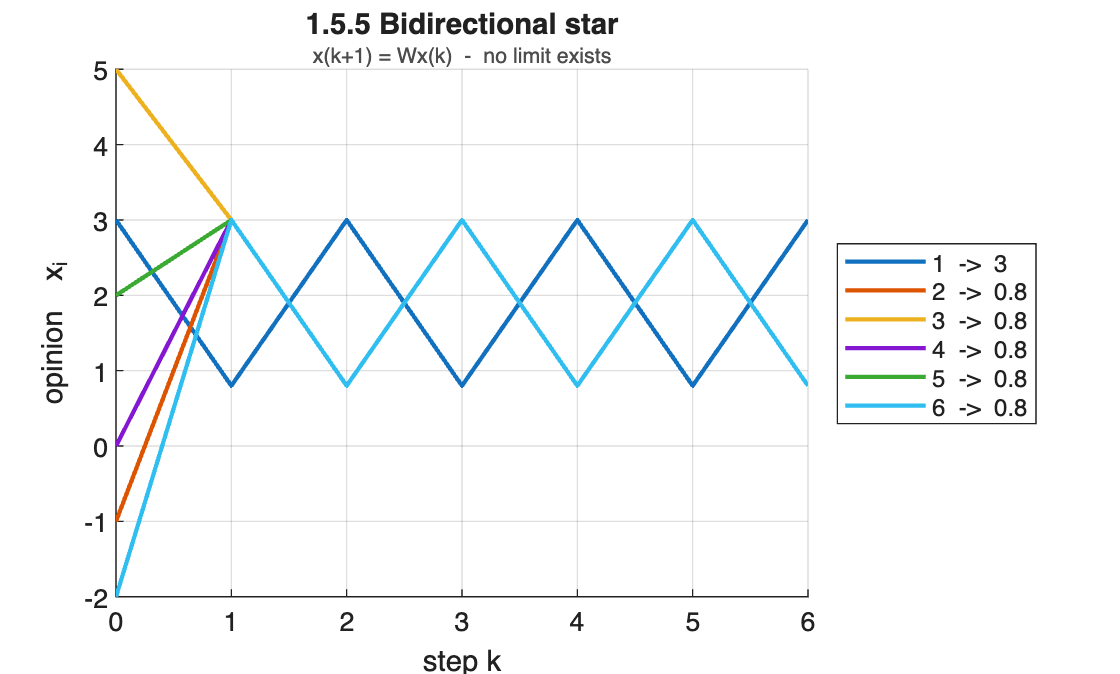

X = sim_degroot(W, x0, 6);
figure; plot_opinions(X, [], 'Title','1.5.5 Bidirectional star', ...
                             'Subtitle','x(k+1) = Wx(k)  -  no limit exists')

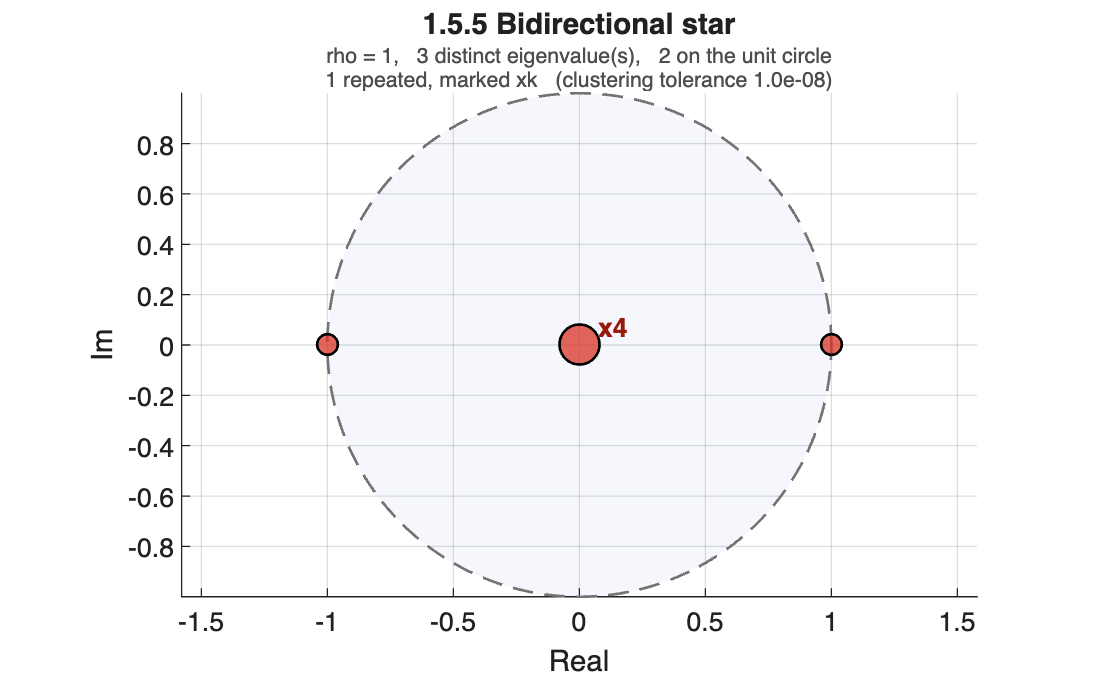

T = 3×5 table
    lambda    Re    Im    modulus    multiplicity
    ______    __    __    _______    ____________

      -1      -1    0        1            1      
       1       1    0        1            1      
       0       0    0        0            4      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','1.5.5 Bidirectional star'); T

The eigenvalue -1 sits on the unit circle beside 1, so the model is not convergent: hub and leaves swap their averages at every step. The spectrum also shows the eigenvalue 0 with multiplicity 4, which the multiplicity marker makes visible; a plain scatter would show a single point at the origin.

### Self-loops on the periphery

Self-loops added to the leaves only, the hub excluded.

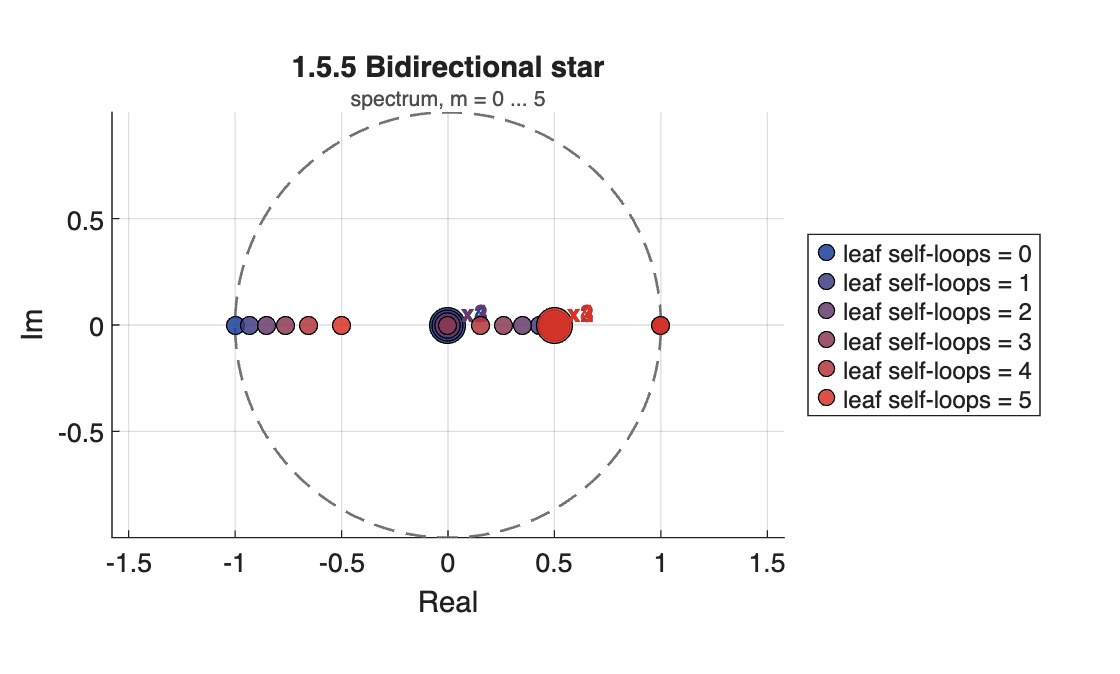

Ms = arrayfun(@(m) row_stochastic(star_graph(N,'bidirectional') + ...
        diag([0; ones(m,1); zeros(N-1-m,1)])), 0:5, 'UniformOutput', false);

figure;
plot_spectrum_family(Ms, 0:5, 'discrete', 'Label','leaf self-loops', ...
    'Title','1.5.5 Bidirectional star', 'Subtitle','spectrum, m = 0 ... 5');

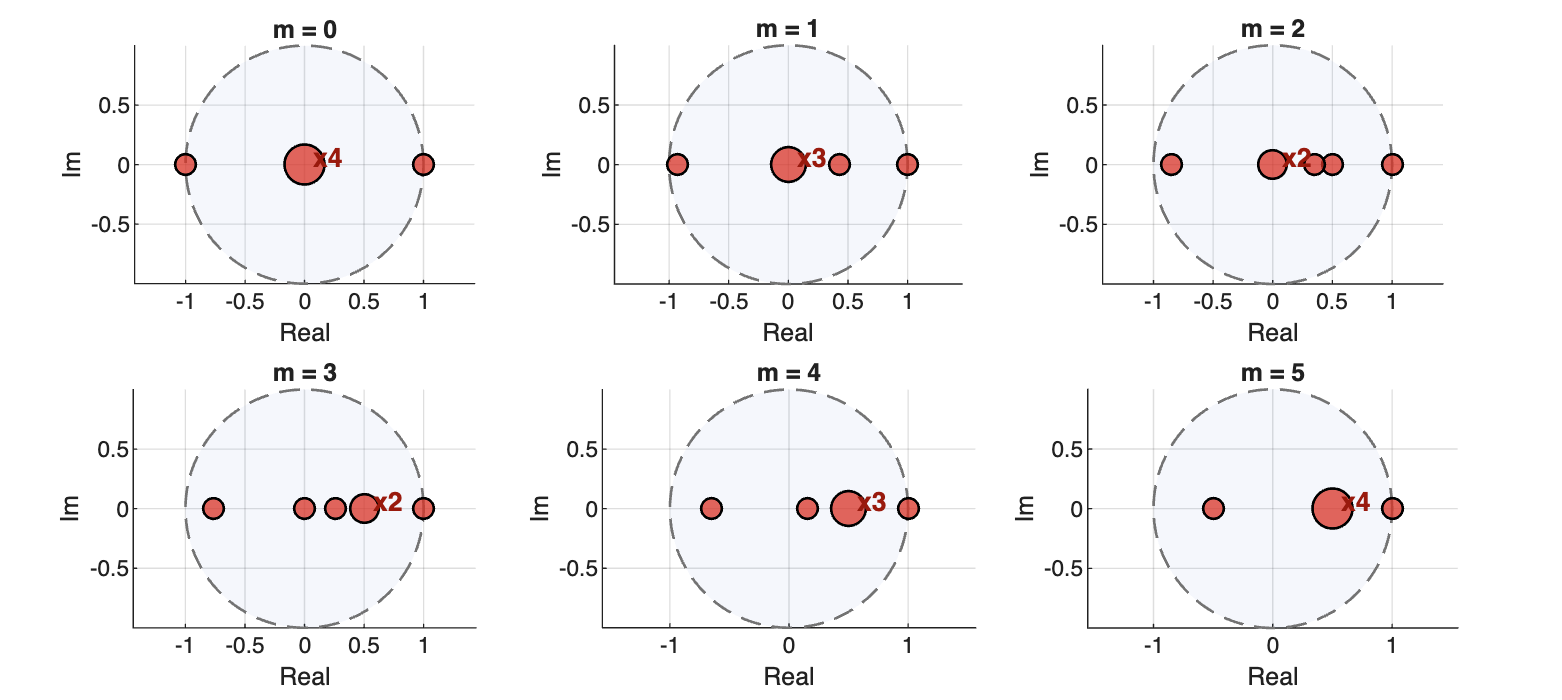

figure('Position',[0 0 1250 560]);
tiledlayout(2, 3, 'TileSpacing','compact', 'Padding','compact');
for m = 0:5
    nexttile;
    plot_eigenvalues(Ms{m+1}, 'discrete', 'Title', sprintf('m = %d', m), 'Subtitle','');
end

The plain leaves and the self-looped leaves each form a symmetry class: mult(0) = 4 - m and mult(1/2) = m - 1.

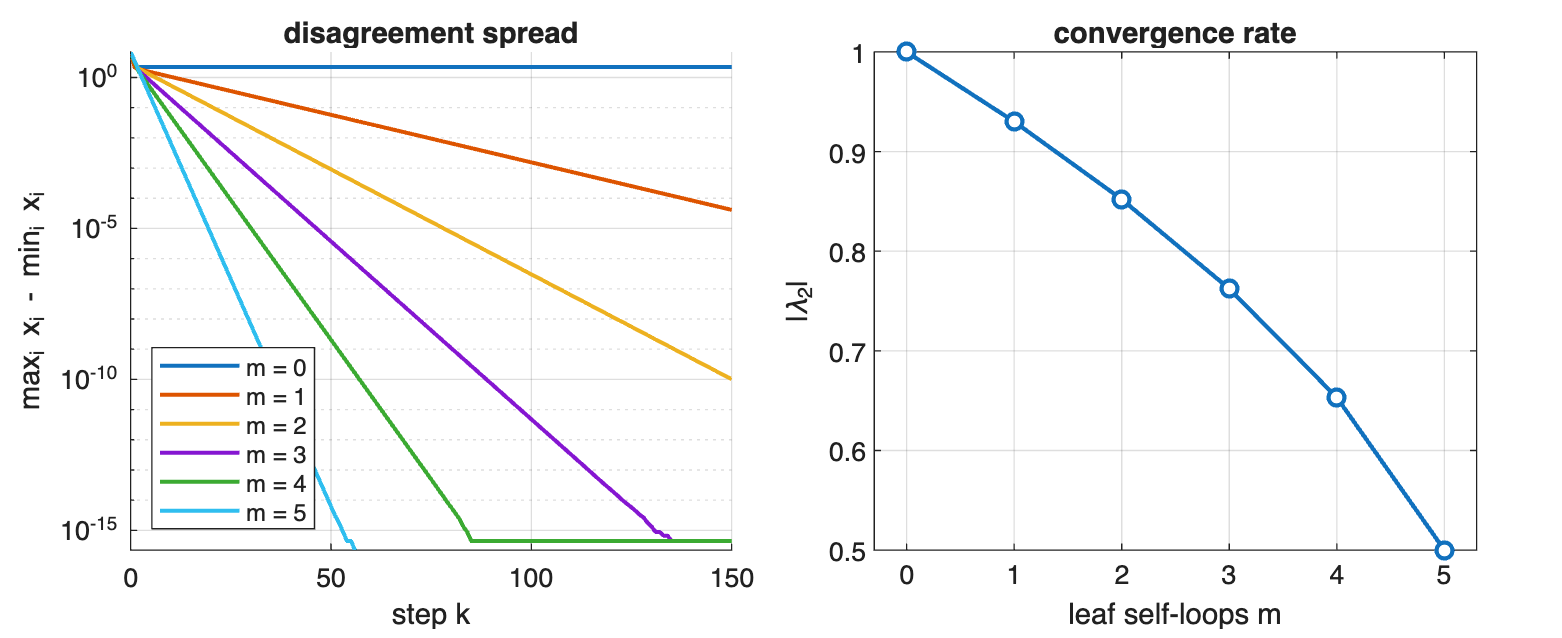

K3 = 150; lam2 = zeros(1, 6);

figure('Position',[0 0 1150 470]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');

nexttile; hold on
for m = 0:5
    X = sim_degroot(Ms{m+1}, x0, K3);
    plot(0:K3, max(X,[],1) - min(X,[],1), 'LineWidth', 1.5, ...
         'DisplayName', sprintf('m = %d', m));
    e = sort(abs(eig(Ms{m+1})), 'descend'); lam2(m+1) = e(2);
end
set(gca, 'YScale', 'log'); grid on; legend('Location','southwest');
xlabel('step k'); ylabel('max_i x_i - min_i x_i');
title('disagreement spread', 'FontWeight','bold');

nexttile
plot(0:5, lam2, 'o-', 'LineWidth', 1.6, 'MarkerFaceColor','w'); grid on
xlabel('leaf self-loops m'); ylabel('|\lambda_2|');
title('convergence rate', 'FontWeight','bold'); xlim([-0.3 5.3]);

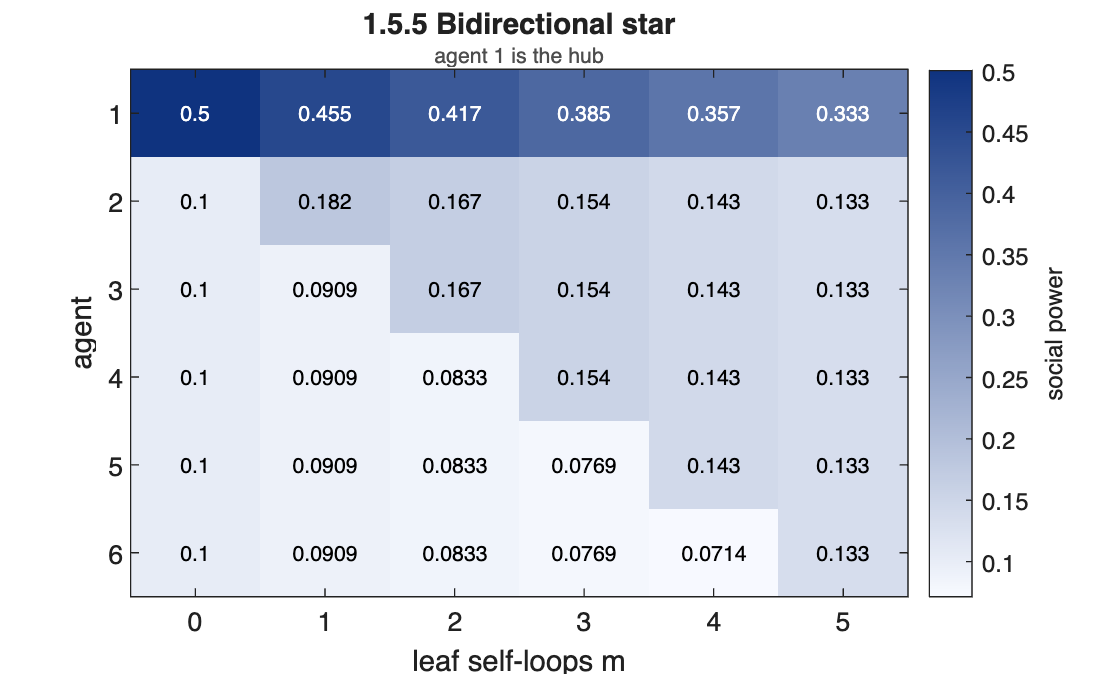

Ps = cell2mat(arrayfun(@(m) social_power(Ms{m+1}), 0:5, 'UniformOutput', false));

figure;
plot_sweep(Ps, 0:5, [], 'Label','leaf self-loops m', 'Name','social power', ...
    'Title','1.5.5 Bidirectional star', 'Subtitle','agent 1 is the hub')

Monotone here, unlike the directed cycle. Hub power 5/(10+m), self-looped leaf 2/(10+m), plain leaf 1/(10+m).

## 1.5.6 Out-star: a topology the standard formulation cannot use

Here the hub listens to all the leaves and the leaves listen to nobody. Their out-degrees are zero, so D_out is singular and the row-stochastic matrix W = D_out^{-1} A does not exist. The topology is perfectly legitimate; it is the normalisation that fails.

The standard remedy is the Perron matrix P = I - eps*L, with eps <= 1 / max_i d_out(i). It is row-stochastic by construction, needs no inverse, and leaves the graph unchanged.

A = common_topology('star-out');
matrix_report(A, 'A');          % the report flags the singular D_out

A   (6 agents)
  out-degrees (row sums): [5 0 0 0 0 0]   row-stochastic : no
  in-degrees  (col sums): [0 1 1 1 1 1]   weight-balanced: no
  strong components  : 6   closed: 5   periods: [0 0 0 0 0 0]
  rooted: no    convergent: yes   consensus: no
  NOTE: agents [2 3 4 5 6] have out-degree 0, so D_out is singular and
        W = D_out^{-1} A does not exist. Use P = I - eps*L.


eps = 1 / max(sum(A,2));        % the largest admissible step
P   = eye(N) - eps * laplacian(A)

P =          0    0.2000    0.2000    0.2000    0.2000    0.2000
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000


s   = matrix_report(P, 'P');

P   (6 agents)
  out-degrees (row sums): [1 1 1 1 1 1]   row-stochastic : yes
  in-degrees  (col sums): [0 1.2 1.2 1.2 1.2 1.2]   weight-balanced: no
  strong components  : 6   closed: 5   periods: [0 1 1 1 1 1]
  rooted: no    convergent: yes   consensus: no


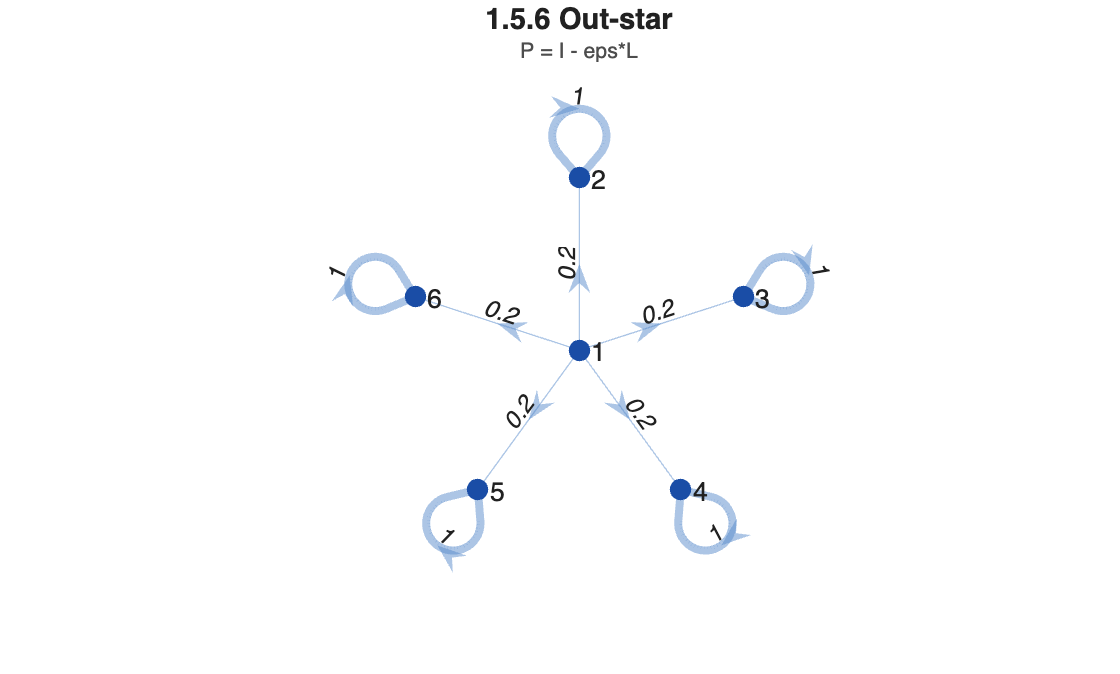

figure; plot_graph(P, [], 'Layout','star', ...
                  'Title','1.5.6 Out-star', 'Subtitle','P = I - eps*L')

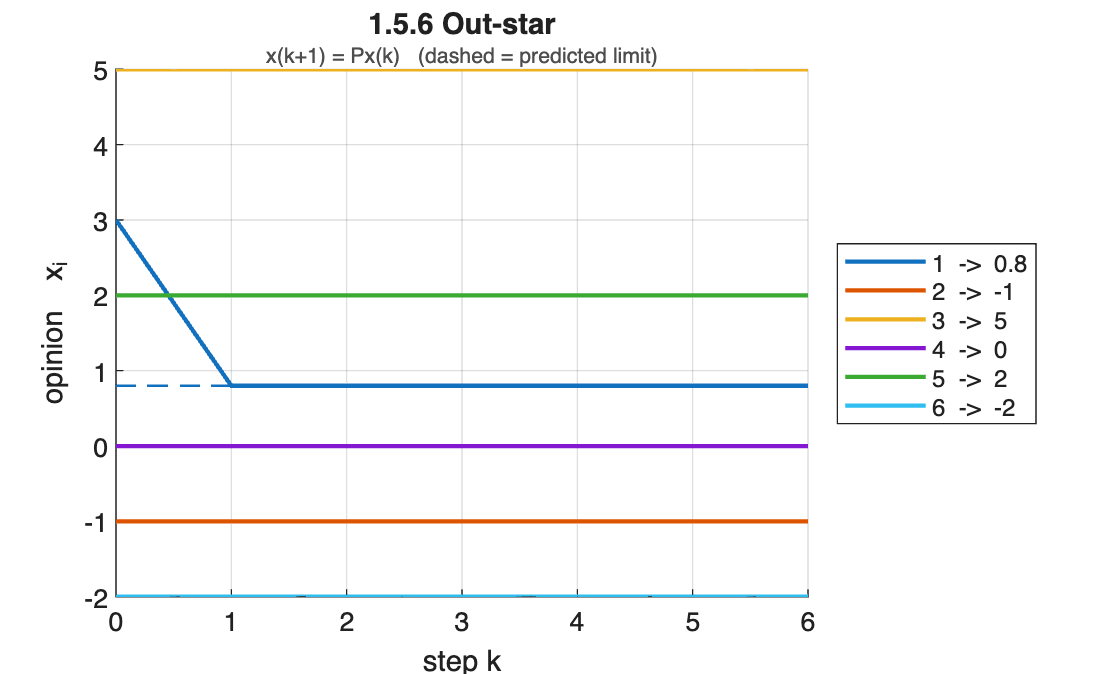

xinf = limit_matrix(P) * x0;
X    = sim_degroot(P, x0, 6);
figure; plot_opinions(X, [], 'Limit', xinf, 'Title','1.5.6 Out-star', ...
                             'Subtitle','x(k+1) = Px(k)   (dashed = predicted limit)')

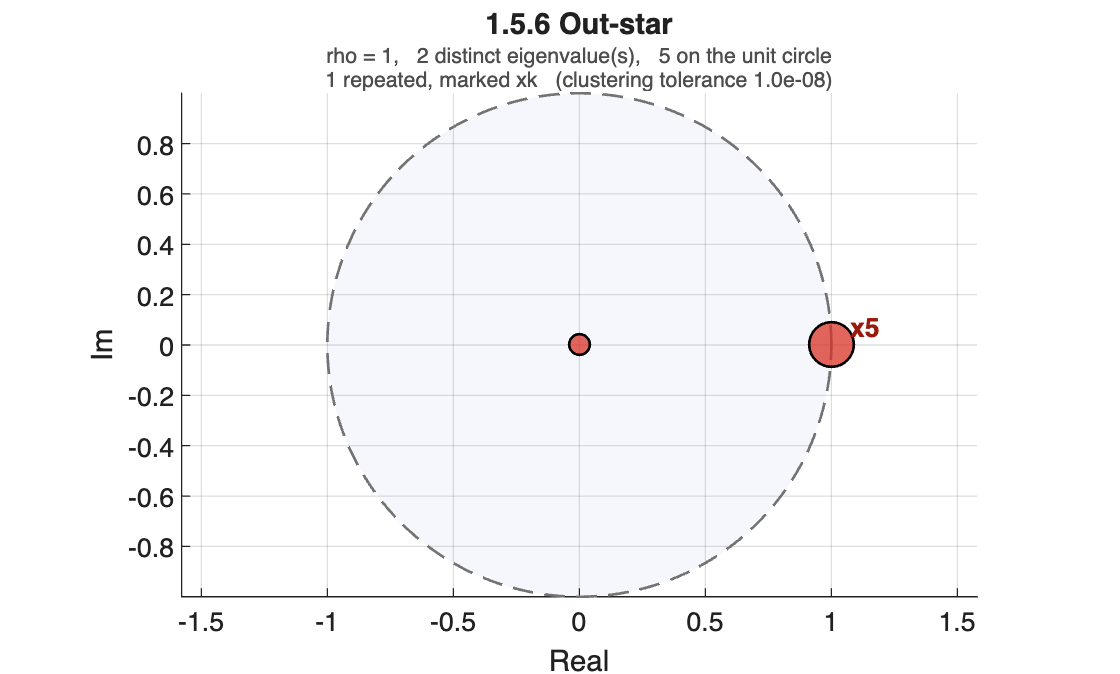

T = 2×5 table
    lambda    Re    Im    modulus    multiplicity
    ______    __    __    _______    ____________

      1       1     0        1            5      
      0       0     0        0            1      


figure; T = plot_eigenvalues(P, 'discrete', 'Title','1.5.6 Out-star'); T

fprintf('x(inf) = %s\n', mat2str(round(xinf.',4)));

x(inf) = [0.8 -1 5 0 2 -2]


fprintf('mean of the leaves = %.4f\n', mean(x0(2:N)));

mean of the leaves = 0.8000


The five leaves have no incoming information and keep their initial opinions forever, so the eigenvalue 1 has multiplicity 5 and consensus is impossible. The hub reaches the average of the leaves in a single step. The model converges, but not to a consensus.

### Choice of eps

P = I - eps*L for four values. Row-stochasticity needs eps <= 1/max_i d_out(i) = 1/5.

epsList = [1/20 1/10 1/5 3/10];
Pe = arrayfun(@(e) eye(N) - e*laplacian(A), epsList, 'UniformOutput', false);
tag = {'no','yes'};

fprintf('   eps    1-5eps   row-stochastic   min entry   rate\n');

   eps    1-5eps   row-stochastic   min entry   rate


for k = 1:numel(epsList)
    ev = eig(Pe{k});
    rate = max(abs(ev(abs(ev - 1) > 1e-8)));     % lambda = 1 is repeated, so not |lambda_2|
    fprintf('  %.3f   %+.3f    %-14s   %+.3f      %.4f\n', epsList(k), 1-5*epsList(k), ...
        tag{1 + is_row_stochastic(Pe{k})}, min(Pe{k}(:)), rate);
end

  0.050   +0.750    yes              +0.000      0.7500
  0.100   +0.500    yes              +0.000      0.5000
  0.200   +0.000    yes              +0.000      0.0000
  0.300   -0.500    no               -0.500      0.5000


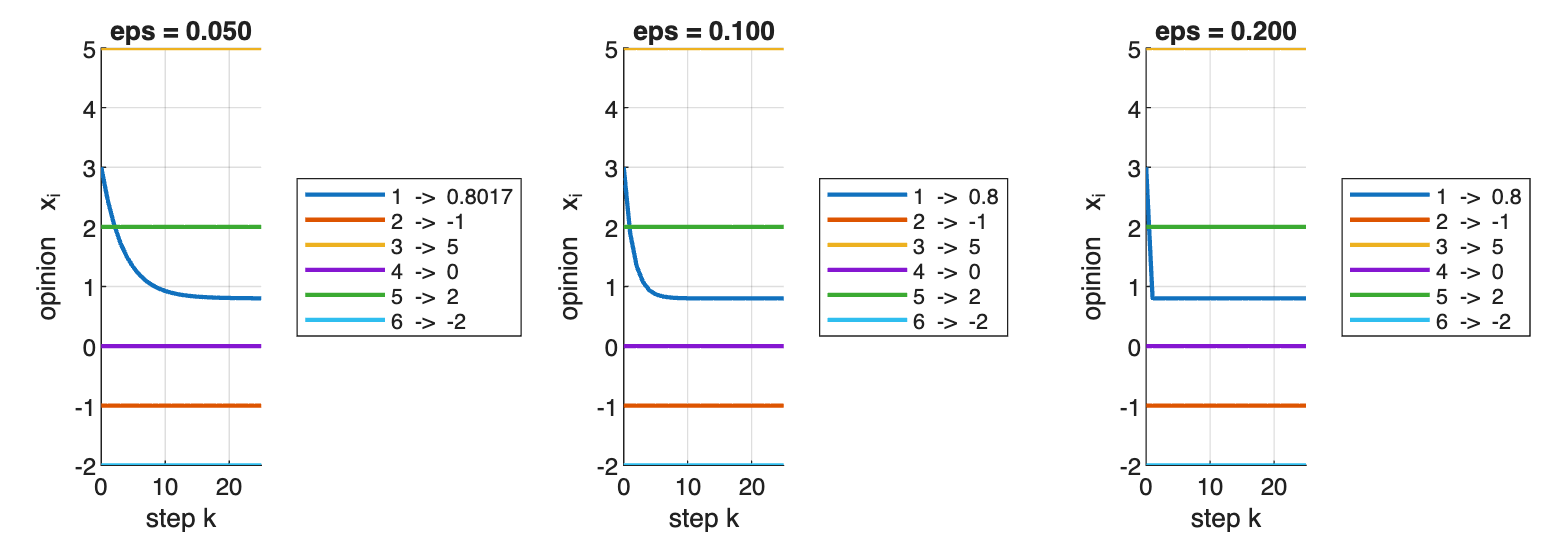

figure('Position',[0 0 1150 400]);
tiledlayout(1, 3, 'TileSpacing','compact', 'Padding','compact');
for k = 1:3                                       % eps = 3/10 is not row-stochastic
    nexttile;
    X = sim_degroot(Pe{k}, x0, 25);
    plot_opinions(X, [], 'Title', sprintf('eps = %.3f', epsList(k)), 'Subtitle','');
end

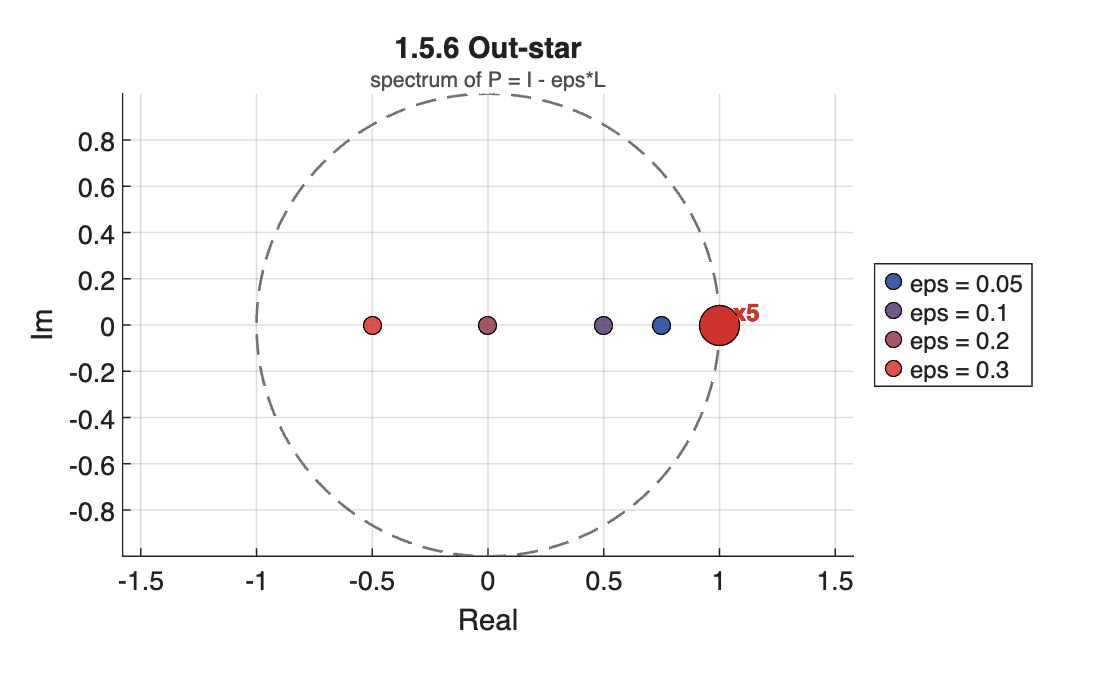

figure;
plot_spectrum_family(Pe, epsList, 'discrete', 'Label','eps', ...
    'Title','1.5.6 Out-star', 'Subtitle','spectrum of P = I - eps*L');

Only 1 - 5*eps moves; lambda = 1 stays with multiplicity 5, so |lambda_2| = 1 for every eps and the rate is the largest modulus among the eigenvalues other than 1. eps = 1/5 is deadbeat; eps = 3/10 makes P(1,1) negative. The limit is 0.8 in every admissible case.

## 1.5.7 Two blocks, a bridge, and stubborn agents

One topology, four settings: the bridge weight, then stubborn agents added one at a time.

W1 = row_stochastic(two_communities(N/2, N/2, 0.02));    % weak bridge
W2 = row_stochastic(two_communities(N/2, N/2, 0.15));    % stronger bridge
W3 = W2;  W3(1,:) = 0;  W3(1,1) = 1;                     % agent 1 stubborn
W4 = W3;  W4(6,:) = 0;  W4(6,6) = 1;                     % agents 1 and 6 stubborn

blocks = {W1, W2, W3, W4};
setting = {'bridge 0.02', 'bridge 0.15', '+ agent 1 stubborn', '+ agents 1 and 6 stubborn'};

s = matrix_report(W4, 'W4');

W4   (6 agents)
  out-degrees (row sums): [1 1 1 1 1 1]   row-stochastic : yes
  in-degrees  (col sums): [1.9651 0.4651 0.5698 0.5698 0.4651 1.9651]   weight-balanced: no
  strong components  : 3   closed: 2   periods: [2 1 1]
  rooted: no    convergent: yes   consensus: no


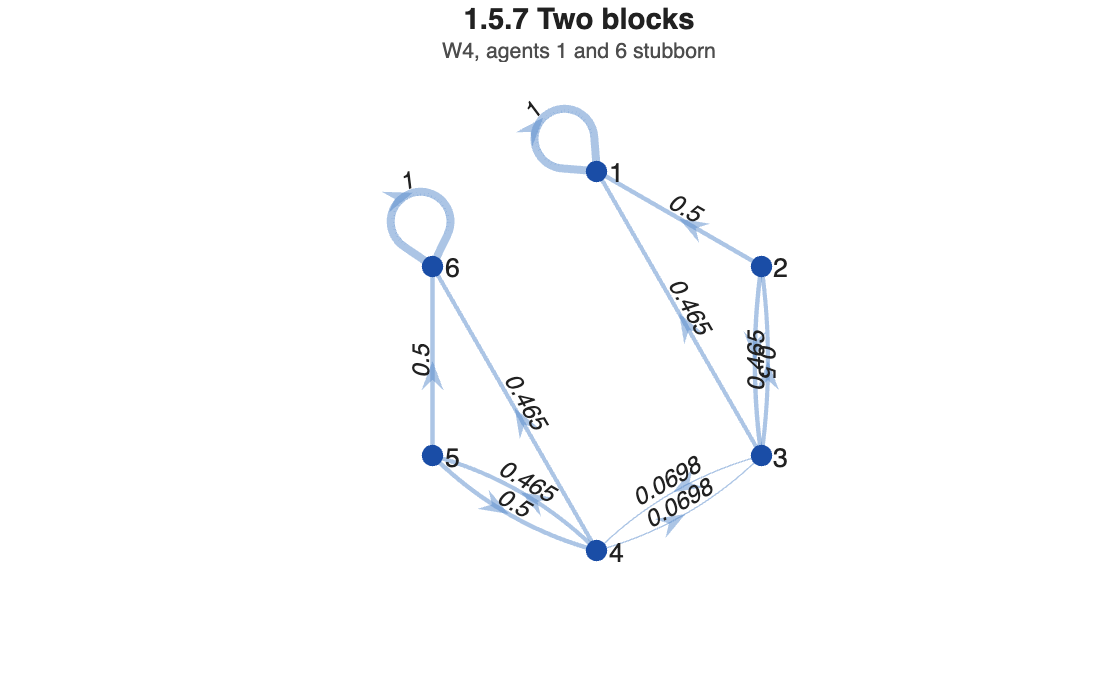

figure; plot_graph(W4, [], 'Title','1.5.7 Two blocks', 'Subtitle','W4, agents 1 and 6 stubborn')

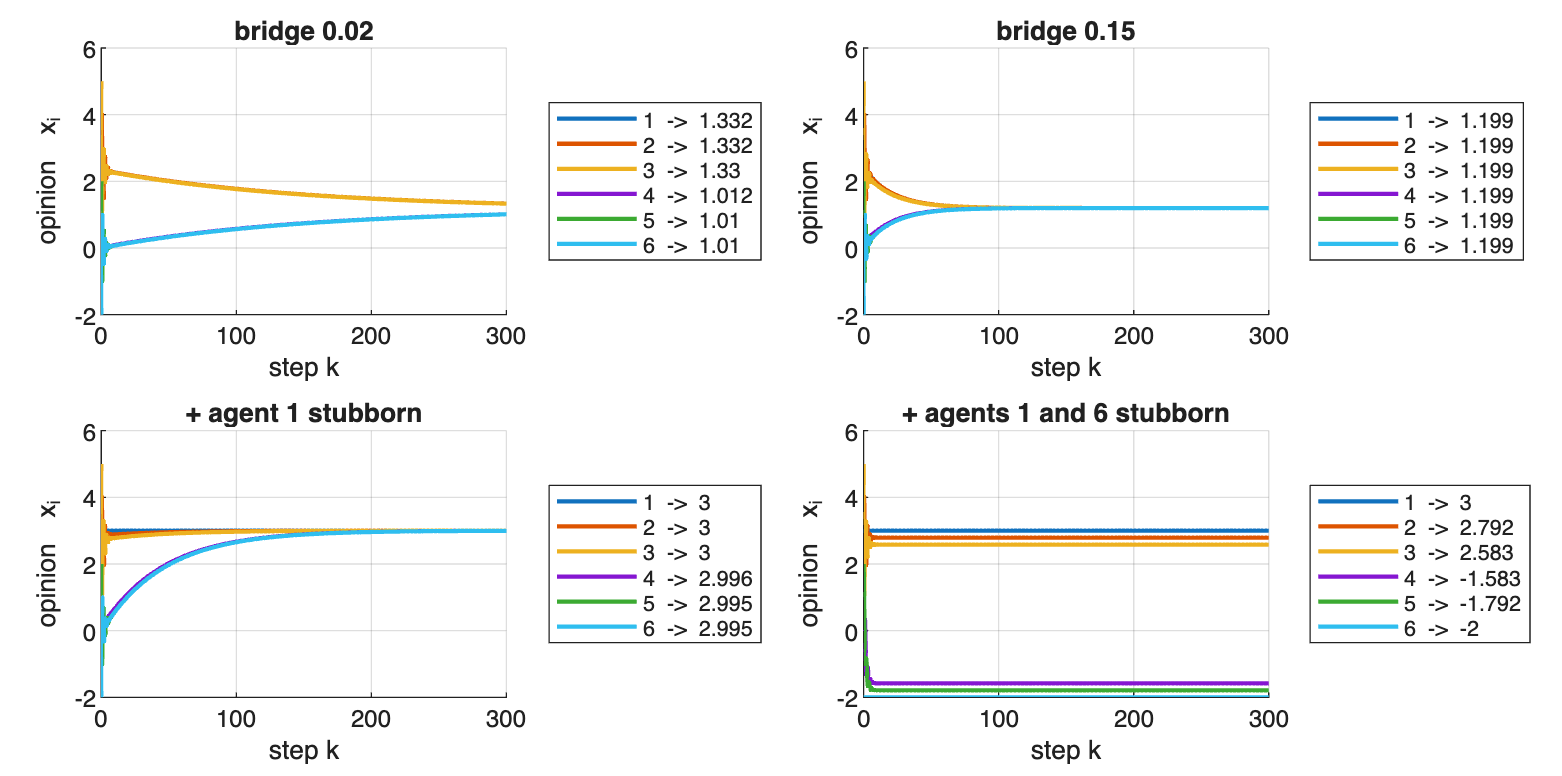

figure('Position',[0 0 1250 620]);
tiledlayout(2, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:4
    nexttile;
    X = sim_degroot(blocks{k}, x0, 300);
    plot_opinions(X, [], 'Title', setting{k}, 'Subtitle','');
end

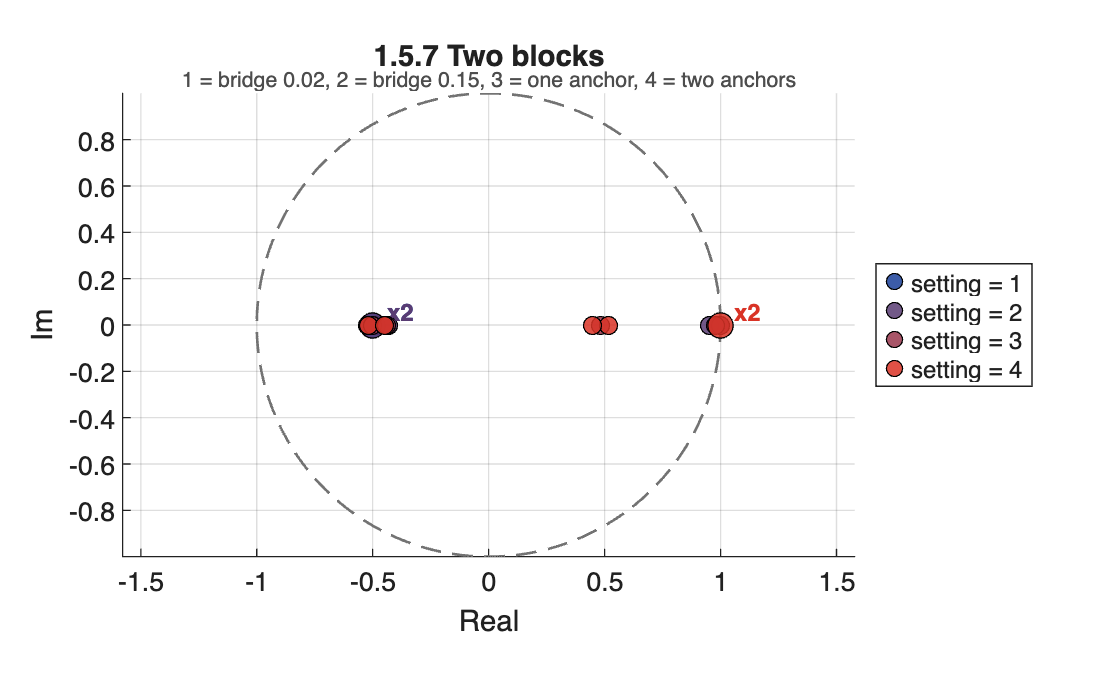

figure;
plot_spectrum_family(blocks, 1:4, 'discrete', 'Label','setting', ...
    'Title','1.5.7 Two blocks', 'Subtitle','1 = bridge 0.02, 2 = bridge 0.15, 3 = one anchor, 4 = two anchors');

rows = cell(4,1);
for k = 1:4
    M = blocks{k};
    g = graph_summary(M);
    Tk = plot_eigenvalues(M, 'discrete', 'Plot', false);
    aev = sort(abs(eig(M)), 'descend');
    rate = max(aev(abs(aev - 1) > 1e-8));
    xinf = limit_matrix(M) * x0;
    rows{k} = {setting{k}, numel(g.closed), g.consensus, ...
               sum(Tk.multiplicity(abs(Tk.lambda - 1) < 1e-8)), ...
               rate, rank(limit_matrix(M)), max(xinf) - min(xinf)};
end
summary = cell2table(vertcat(rows{:}), 'VariableNames', ...
    {'setting','closed','consensus','mult_lambda1','rate','rank_Winf','final_spread'})

summary = 4×7 table
               setting               closed    consensus    mult_lambda1     rate      rank_Winf    final_spread
    _____________________________    ______    _________    ____________    _______    _________    ____________

    {'bridge 0.02'              }      1         true            1          0.99341        1         2.2204e-16 
    {'bridge 0.15'              }      1         true            1          0.95422        1                  0 
    {'+ agent 1 stubborn'       }      1         true            1          0.97853        1                  0 
    {'+ agents 1 and 6 stubborn'}      2         false           2          0.51839        2                  5 


One anchor gives consensus at that agents opinion; two anchors give convergence without consensus, with lambda = 1 of multiplicity 2 in a connected graph and the free agents spread between the anchors.

## 1.5.8 Comparison

The same model on six topologies. The multiplicity of the eigenvalue 1 is the quantity that decides the outcome: 1 gives consensus, more than 1 gives disagreement, and an eigenvalue of modulus 1 other than 1 itself gives no limit at all.

recapCases = { ...
    'bidirectional cycle',  row_stochastic(ring_graph(N) + ring_graph(N).'); ...
    'directed cycle',       row_stochastic(ring_graph(N)); ...
    'cycle + 1 self-loop',  row_stochastic(ring_graph(N) + diag([1; zeros(N-1,1)])); ...
    'line',                 row_stochastic(path_graph(N)); ...
    'bidirectional star',   row_stochastic(star_graph(N,'bidirectional')); ...
    'star + 3 leaf loops',  row_stochastic(star_graph(N,'bidirectional') + diag([0;1;1;1;0;0])); ...
    'out-star, eps = 1/5',  eye(N) - (1/5)*laplacian(common_topology('star-out')); ...
    'blocks + 2 stubborn',  W4};

rows = cell(size(recapCases,1), 1);
for i = 1:size(recapCases,1)
    M = recapCases{i,2};
    g = graph_summary(M);
    Ti = plot_eigenvalues(M, 'discrete', 'Plot', false);
    mult1    = sum(Ti.multiplicity(abs(Ti.lambda - 1) < 1e-8));
    onCircle = sum(Ti.multiplicity(abs(abs(Ti.lambda) - 1) < 1e-8));
    if g.convergent
        xinf = limit_matrix(M) * x0;
        spread = max(xinf) - min(xinf);
    else
        spread = NaN;
    end
    rows{i} = {recapCases{i,1}, g.rooted, g.convergent, g.consensus, mult1, onCircle, spread};
end

recap = cell2table(vertcat(rows{:}), 'VariableNames', ...
    {'topology','rooted','convergent','consensus','mult_lambda1','on_unit_circle','final_spread'})

recap = 8×7 table
           topology            rooted    convergent    consensus    mult_lambda1    on_unit_circle    final_spread
    _______________________    ______    __________    _________    ____________    ______________    ____________

    {'bidirectional cycle'}    true        false         false           1                2                   NaN 
    {'directed cycle'     }    true        false         false           1                6                   NaN 
    {'cycle + 1 self-loop'}    true        true          true            1                1            4.4409e-16 
    {'line'               }    true        true          true            1                1                     0 
    {'bidirectional star' }    true        false     

Reading the table: consensus holds exactly when the graph is rooted and the eigenvalue 1 is simple. The cycle and the star are rooted but carry extra eigenvalues on the unit circle, so they never settle. The out-star and the two blocks settle but disagree, and the multiplicity of 1 counts the number of independent limits.